clear ;
close all;

tic
load ryan3_data.mat
toc 

Elapsed time is 1.351235 seconds.


generate_model = true

generate_model = logical
   1


if generate_model == false
    load ryan3_model_Vd_RUL.mat
end

%generate_model = false
% https://kr.mathworks.com/help/matlab/ref/load.html
%load('ryan3_gen_data.mat','battery_dataset')


# 선형회귀 모델 생성

if generate_model
    
tic
mdl_Vd_RUL = fitlm(x_trainValid_Vd_RUL,y_trainValid_RUL)
toc

ryan3_model_Vd_RUL_desc = 'ryan3_model_Vd_RUL_desc';
save('ryan3_model_Vd_RUL.mat','ryan3_model_Vd_RUL_desc')
save('ryan3_model_Vd_RUL.mat','mdl_Vd_RUL')

end

mdl_Vd_RUL = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20

Estimated Coefficients:
                   Estimate        SE         tStat        pValue   
                   _________    _________    ________    ___________

    (Intercept)     0.072003      0.10587     0.68011        0.49644
    x1              0.076474    0.0058875      12.989     1.6979e-38
    x2               -41.823       1.1959     -34.972    8.4598e-264
    x3                68.125       2.9022      23.473    5.4777e-121
    x4               -9.7498       3.0022     -3.2476       0.001165
    x5               -42.182       2.7649     -15.256     2.1417e-52
    x6         </

Elapsed time is 0.246639 seconds.


# 선형회귀 예측

coeff = mdl_Vd_RUL.Coefficients.Estimate

coeff =     0.0720
    0.0765
  -41.8229
   68.1246
   -9.7498
  -42.1817
  -25.6495
    3.9746
   84.7165
   -9.1055


x_trainValid_Vd_RUL(1,:)

ans =     0.7824    0.9237    0.9115    0.9030    0.8947    0.8860    0.8763    0.8659    0.8547    0.8420    0.8269    0.8077    0.7815    0.7425    0.6766    0.5473    0.2364    0.0019    0.0019    0.0019


training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

yhat = x_trainValid_Vd_RUL*coeff(2:21)+coeff(1)

yhat =     0.4054
    0.4055
    0.3967
    0.4009
    0.3989
    0.4000
    0.3895
    0.3960
    0.3856
    0.3852


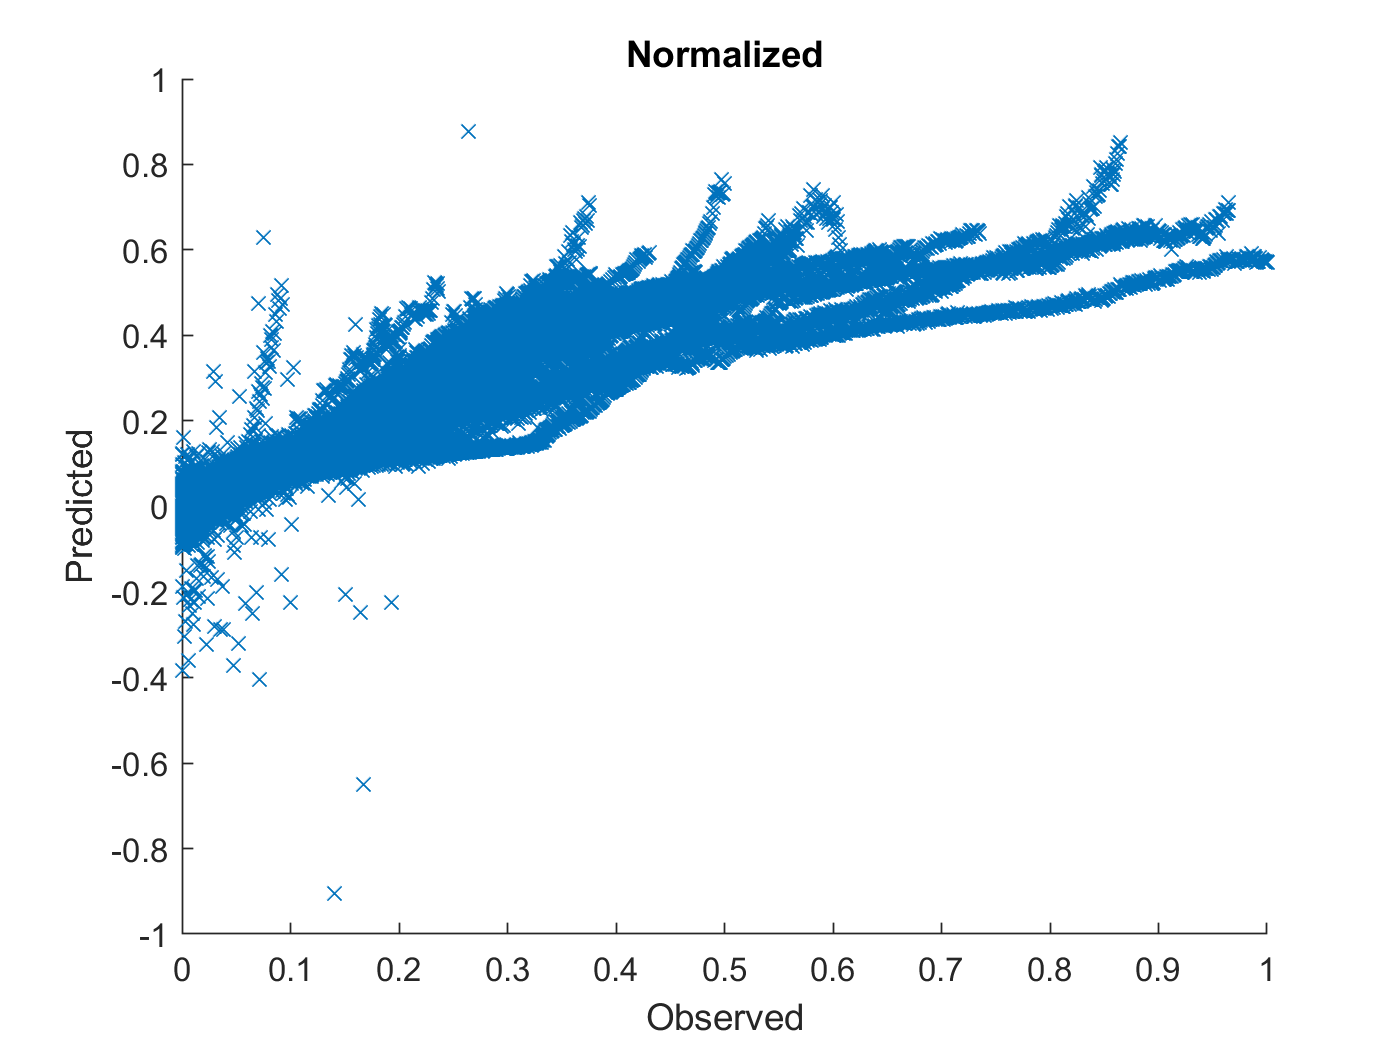

figure
hold on
plot(y_trainValid_RUL,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Normalized'

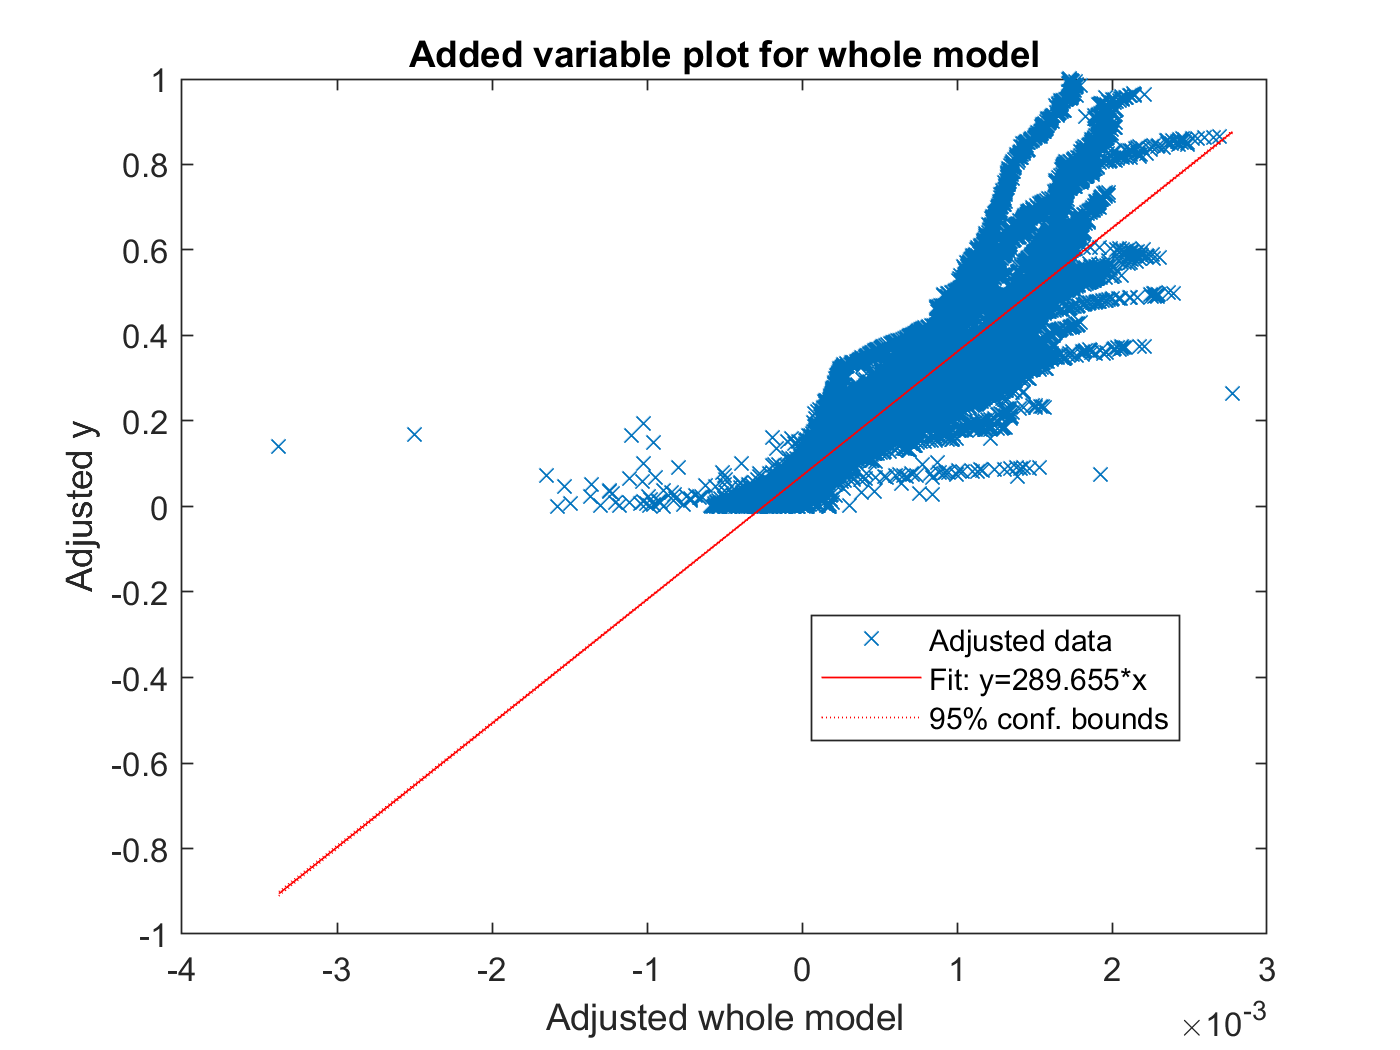


%capHat = Ic(1)

plot(mdl_Vd_RUL)

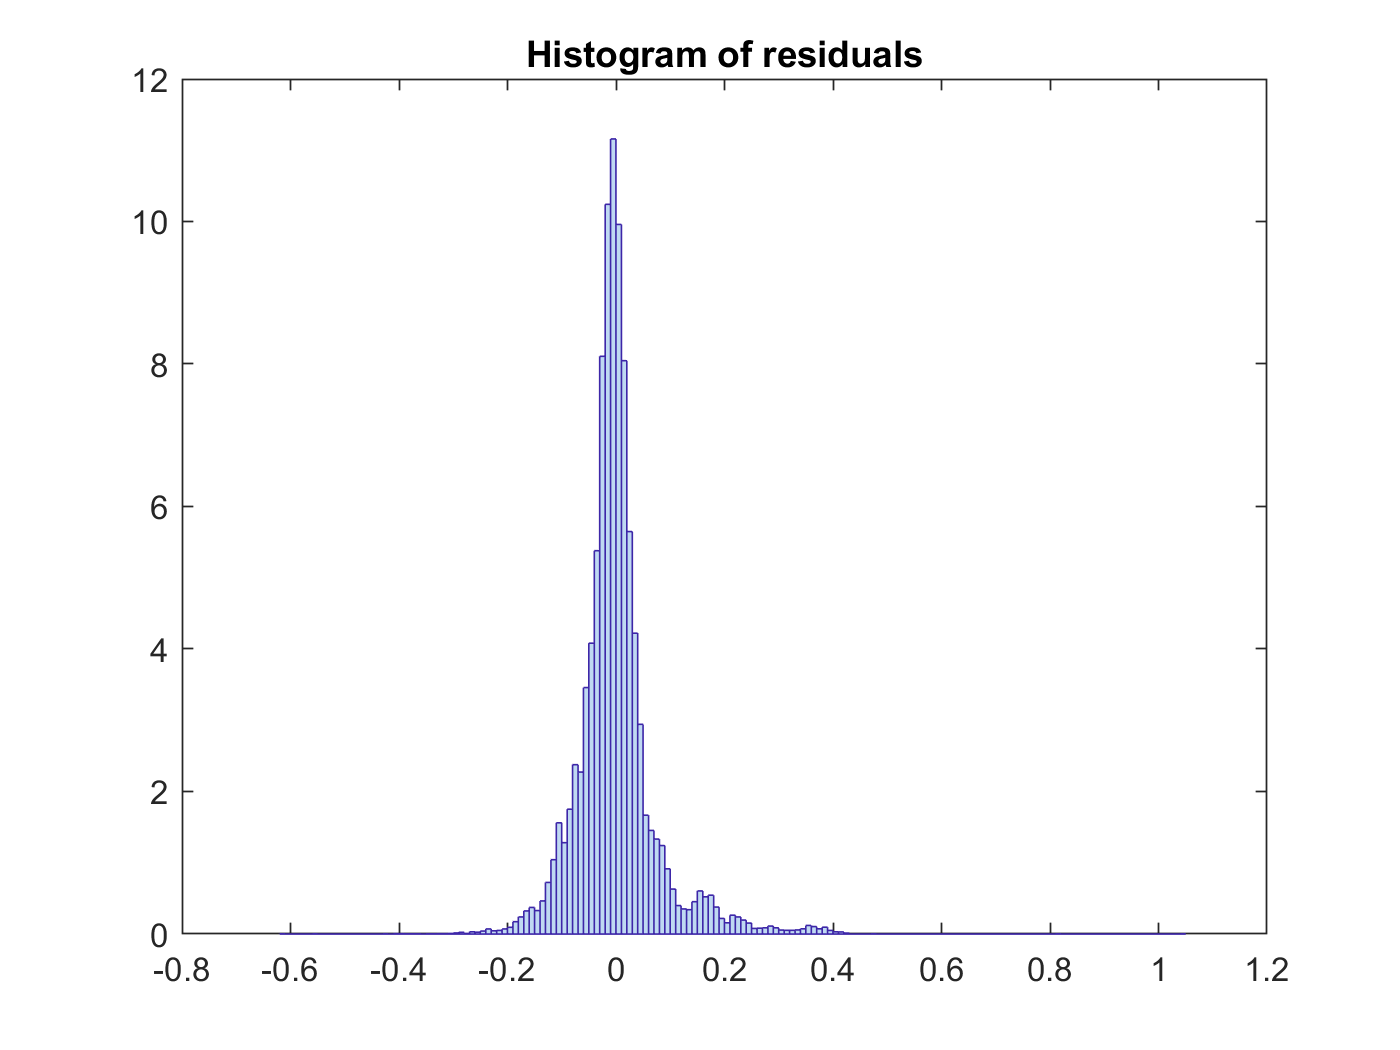

plotResiduals(mdl_Vd_RUL)




% yfit = predict(mdl_Vd_RUL,Ic)
yfit = predict(mdl_Vd_RUL,x_trainValid_Vd_RUL)

yfit =     0.4054
    0.4055
    0.3967
    0.4009
    0.3989
    0.4000
    0.3895
    0.3960
    0.3856
    0.3852


yfit_test = predict(mdl_Vd_RUL,x_test_Vd_RUL)

yfit_test =     0.3422
    0.3535
    0.3553
    0.3406
    0.3339
    0.3404
    0.3361
    0.3428
    0.3400
    0.3411




y= y_trainValid_RUL

y =     0.3650
    0.3641
    0.3632
    0.3624
    0.3615
    0.3607
    0.3598
    0.3590
    0.3581
    0.3573


y_test_RUL

y_test_RUL =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


# denormaize

yfit = yfit * yrate_RUL + ymin_RUL;
y = y * yrate_RUL + ymin_RUL;
yfit_test = yfit_test * yrate_RUL + ymin_RUL;

MAE = mean(abs(yfit-y))

MAE = 55.2387

adjMAE = MAE/range(y)

adjMAE = 0.0472

range(y) % y = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(y - yhat)    % Errors

ans = 	1.0e+03 *

    0.4276
    0.4266
    0.4256
    0.4246
    0.4236
    0.4226
    0.4216
    0.4206
    0.4196
    0.4186


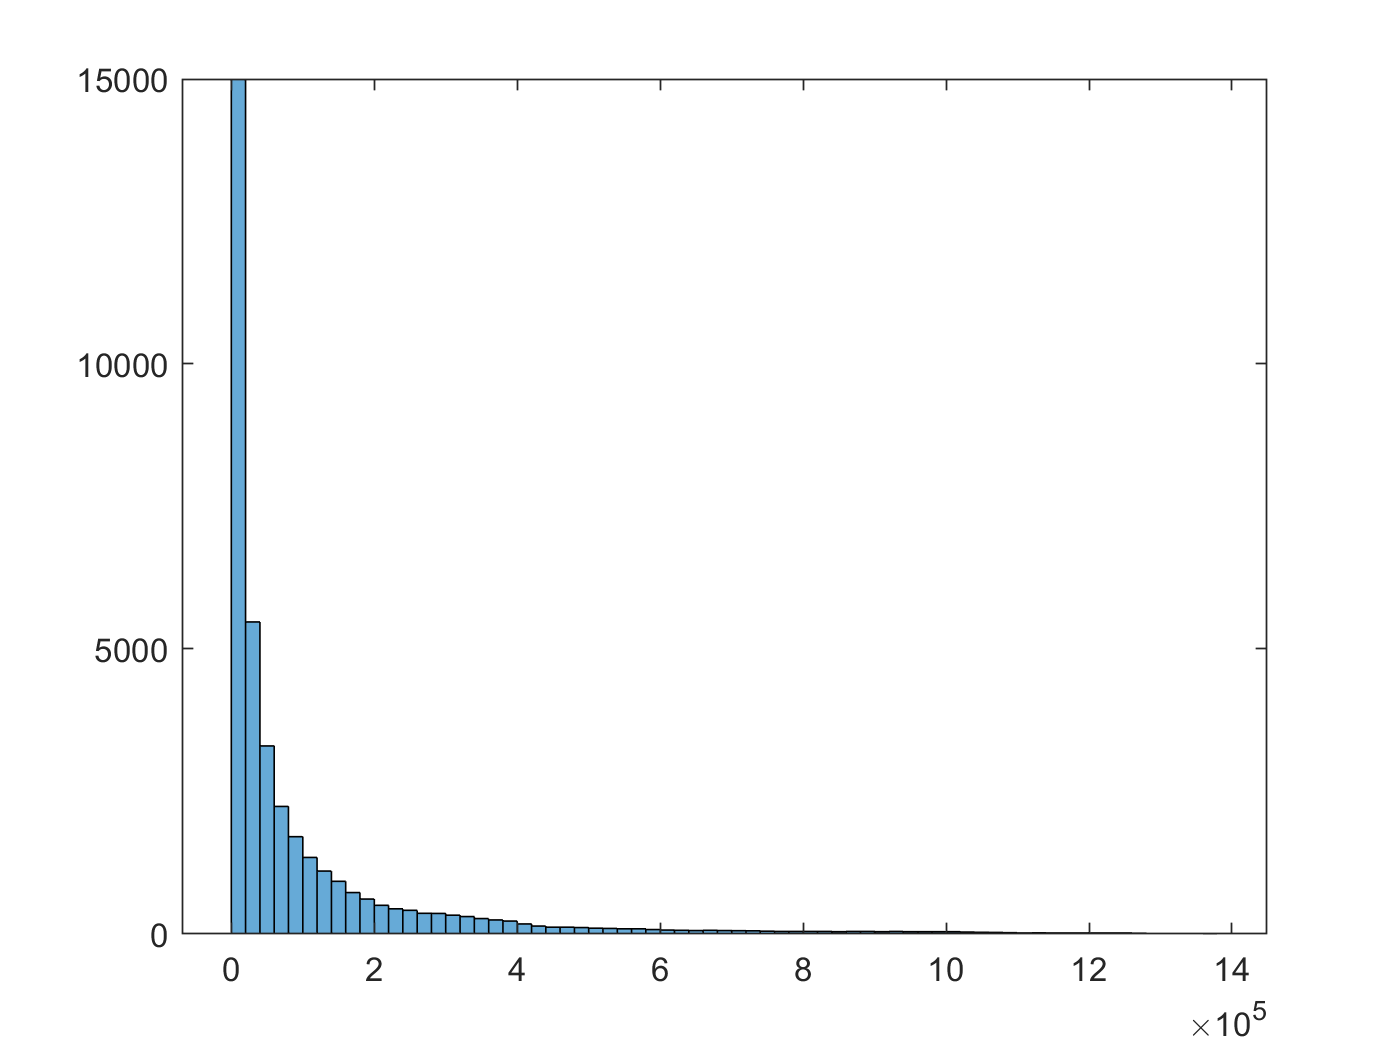

(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 327.7530

y_diff = horzcat(y,(y-yfit))

y_diff = 	1.0e+03 *

    0.4280   -0.0473
    0.4270   -0.0485
    0.4260   -0.0392
    0.4250   -0.0451
    0.4240   -0.0437
    0.4230   -0.0460
    0.4220   -0.0347
    0.4210   -0.0433
    0.4200   -0.0322
    0.4190   -0.0326


y_diff_percentage = abs(y-yfit)./y.*100

y_diff_percentage = 	1.0e+04 *

    0.0011
    0.0011
    0.0009
    0.0011
    0.0010
    0.0011
    0.0008
    0.0010
    0.0008
    0.0008


length(y_diff_percentage)

ans = 38367

y_diff_percentage_avg = sum(y_diff_percentage)/length(y_diff_percentage)

y_diff_percentage_avg = 58.7681


(Y_test_Vd_RUL - yfit_test) 

ans =   -85.3383
  -99.5801
 -102.6769
  -86.5351
  -79.6134
  -88.2658
  -84.2766
  -93.0628
  -90.7927
  -93.0435


RMSE_test = sqrt(mean((Y_test_Vd_RUL - yfit_test).^2))

RMSE_test = 94.3264

y_diff_test = horzcat(Y_test_Vd_RUL,(Y_test_Vd_RUL-yfit_test))

y_diff_test = 	1.0e+03 *

    0.3160   -0.0853
    0.3150   -0.0996
    0.3140   -0.1027
    0.3130   -0.0865
    0.3120   -0.0796
    0.3110   -0.0883
    0.3100   -0.0843
    0.3090   -0.0931
    0.3080   -0.0908
    0.3070   -0.0930


y_diff_test_percentage = abs(Y_test_Vd_RUL-yfit_test)./Y_test_Vd_RUL.*100

y_diff_test_percentage = 	1.0e+03 *

    0.0270
    0.0316
    0.0327
    0.0276
    0.0255
    0.0284
    0.0272
    0.0301
    0.0295
    0.0303


y_diff_test_percentage_avg = sum(y_diff_test_percentage)/length(y_diff_test_percentage)

y_diff_test_percentage_avg = 49.1447

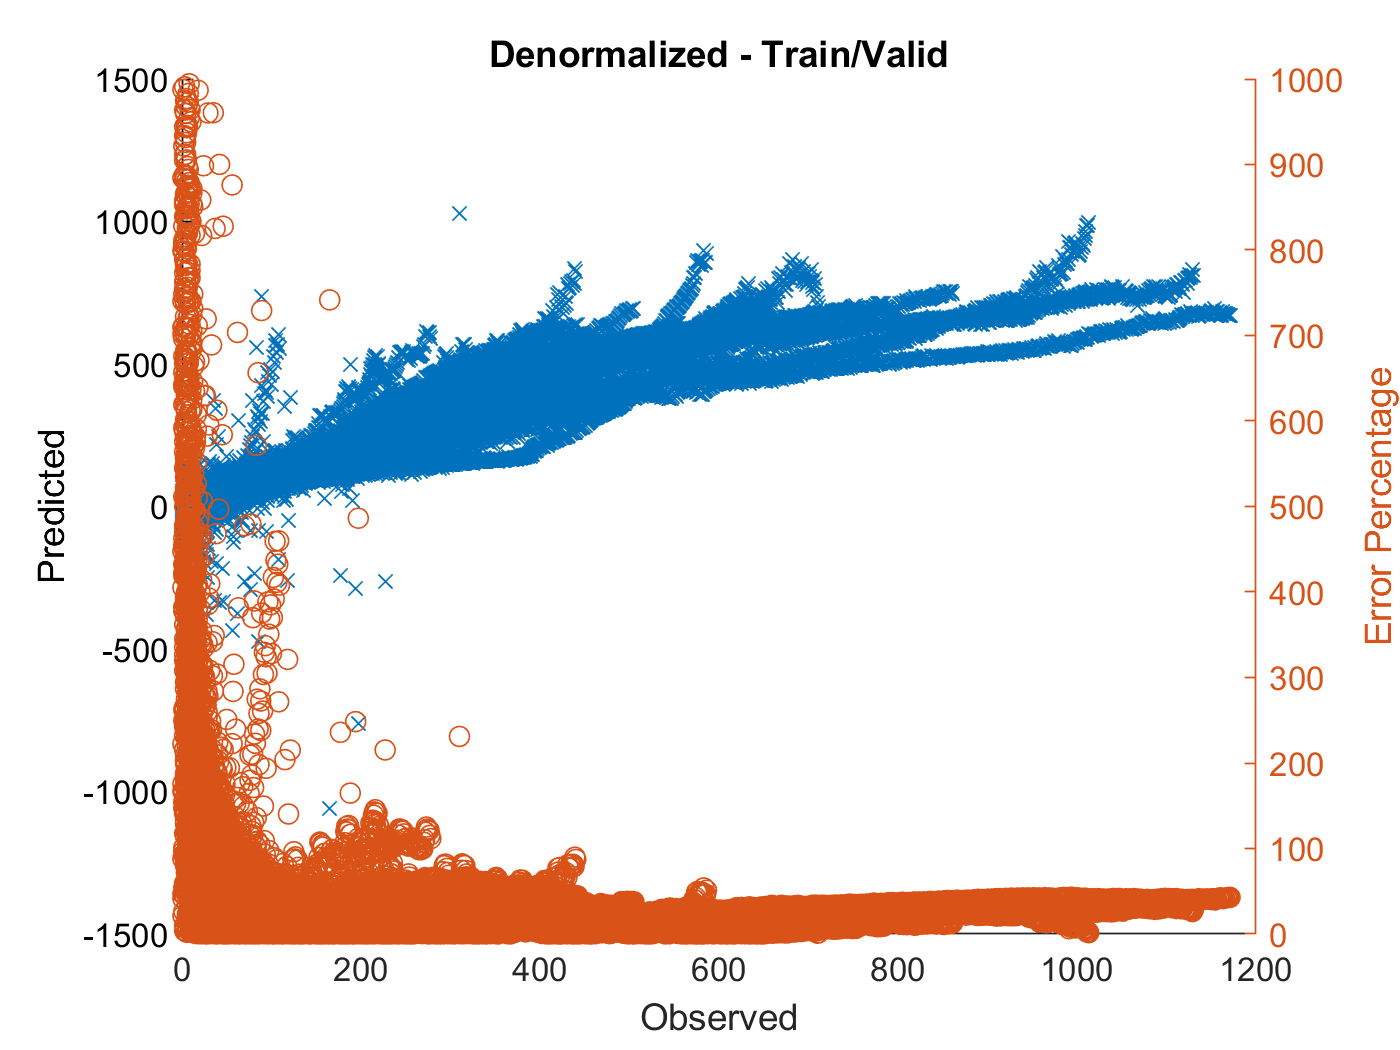


figure
hold on
plot(y,yfit,'x')
xlabel("Observed")
ylabel("Predicted")

yyaxis right
ylabel('Error Percentage')
plot(y,y_diff_percentage,'o');
ylim([0 1000])

hold off
title 'Denormalized - Train/Valid'

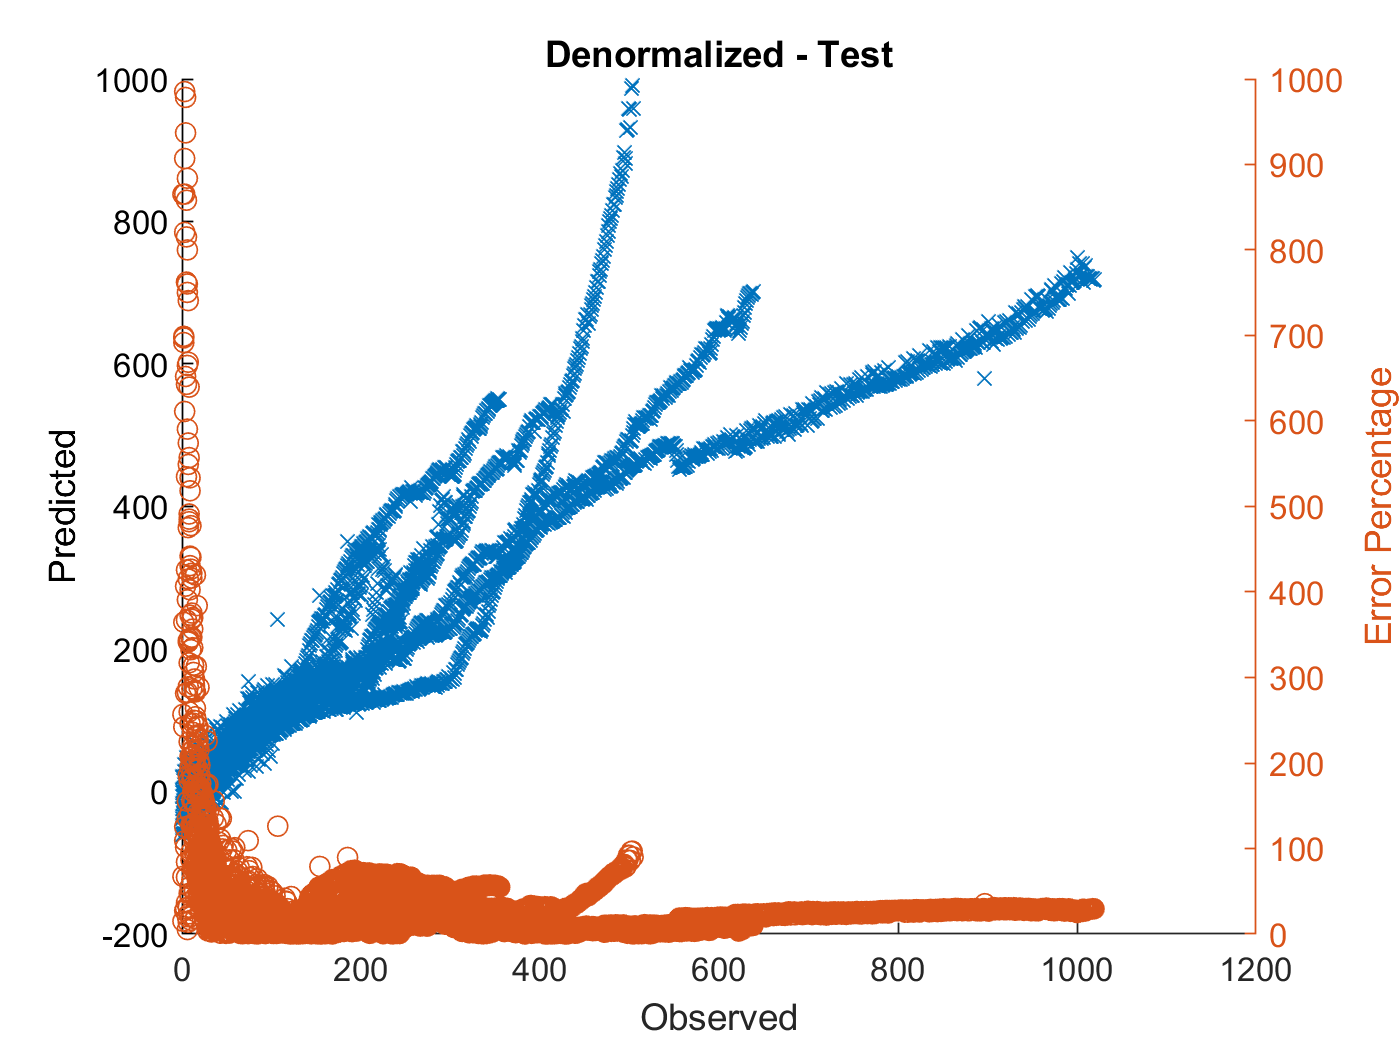


figure
hold on
plot(Y_test_Vd_RUL,yfit_test,'x')
xlabel("Observed")
ylabel("Predicted")

yyaxis right
ylabel('Error Percentage')
plot(Y_test_Vd_RUL,y_diff_test_percentage,'o');
ylim([0 1000])

hold off
title 'Denormalized - Test'

%xlim([0 1200]), ylim([0 1200])

% 테스트 셋에서는 예측이 전혀 안된다.


# 머신러닝을 위한 기본 설정

epoc_count = 5;
epoc_count_lstm = 3;
%epoc_count = 10; % 시간이 너무 오래 걸린다.
cc_input_size = 20;

# FNN 모델 생성

- FNN1 - 1 layer

if generate_model
netFNN1_1 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_1.divideFcn = 'divideind';
netFNN1_1.divideParam.trainInd = idxTrainAll;
netFNN1_1.divideParam.valInd = idxValidAll;
netFNN1_1.divideParam.testInd = idxTestAll; 
    
%netFNN1__1.divideParam
% https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
netFNN1_1.trainParam.showWindow = 0; 
netFNN1_1.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
[netFNN1_1, tr] = train(netFNN1_1, xnorm_Vd_RUL', ynorm_Vd_RUL', 'useparallel',  'yes');
toc
%tr

netFNN1_2 = feedforwardnet(20); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_2.divideFcn = 'divideind';

netFNN1_2.divideFcn = 'divideind';
netFNN1_2.divideParam.trainInd = idxTrainAll;
netFNN1_2.divideParam.valInd = idxValidAll;
netFNN1_2.divideParam.testInd = idxTestAll; 
    
%netFNN1_2.divideParam
netFNN1_2.trainParam.showWindow = 0; 
netFNN1_2.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
netFNN1_2 = train(netFNN1_2, xnorm_Vd_RUL', ynorm_Vd_RUL', 'useparallel',  'yes');
toc


netFNN1_3 = feedforwardnet(100); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_3.divideFcn = 'divideind';

netFNN1_3.divideFcn = 'divideind';
netFNN1_3.divideParam.trainInd = idxTrainAll;
netFNN1_3.divideParam.valInd = idxValidAll;
netFNN1_3.divideParam.testInd = idxTestAll; 
    
%netFNN1_3.divideParam
netFNN1_3.trainParam.showWindow = 0; 
netFNN1_3.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
netFNN1_3 = train(netFNN1_3, xnorm_Vd_RUL', ynorm_Vd_RUL', 'useparallel',  'yes');
toc


netFNN2_1 = feedforwardnet([20,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_1.divideParam.trainInd = idxTrainAll;
netFNN2_1.divideParam.valInd = idxValidAll;
netFNN2_1.divideParam.testInd = idxTestAll; 

netFNN2_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_1.trainParam.showWindow = 0;
netFNN2_1.trainParam.show = NaN;
tic
[netFNN2_1, tr2] = train(netFNN2_1, xnorm_Vd_RUL', ynorm_Vd_RUL', 'useparallel',  'yes');
toc
%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN2_2 = feedforwardnet([50,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_2.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_2.divideParam.trainInd = idxTrainAll;
netFNN2_2.divideParam.valInd = idxValidAll;
netFNN2_2.divideParam.testInd = idxTestAll; 

netFNN2_2.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_2.trainParam.show = NaN;
netFNN2_2.trainParam.showWindow = 0;
tic
netFNN2_2 = train(netFNN2_1, xnorm_Vd_RUL', ynorm_Vd_RUL', 'useparallel',  'yes');
toc
%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN3_1 = feedforwardnet([50,20,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN3_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN3_1.divideParam.trainInd = idxTrainAll;
netFNN3_1.divideParam.valInd = idxValidAll;
netFNN3_1.divideParam.testInd = idxTestAll; 

netFNN3_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN3_1.trainParam.show = NaN;
netFNN3_1.trainParam.showWindow = 0;
tic
netFNN3_1 = train(netFNN3_1, xnorm_Vd_RUL', ynorm_Vd_RUL', 'useparallel',  'yes');
toc
%view(netFNN3_1)


netFNN4_1 = feedforwardnet([50,20,10,5]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN4_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN4_1.divideParam.trainInd = idxTrainAll;
netFNN4_1.divideParam.valInd = idxValidAll;
netFNN4_1.divideParam.testInd = idxTestAll; 

netFNN4_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN4_1.trainParam.show = NaN;
netFNN4_1.trainParam.showWindow = 0;
tic
netFNN4_1 = train(netFNN4_1, xnorm_Vd_RUL', ynorm_Vd_RUL', 'useparallel',  'yes');
toc
%view(netFNN3_1)


netFNN5_1 = feedforwardnet([50,20,10,5,5]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN5_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN5_1.divideParam.trainInd = idxTrainAll;
netFNN5_1.divideParam.valInd = idxValidAll;
netFNN5_1.divideParam.testInd = idxTestAll; 

netFNN5_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN5_1.trainParam.show = NaN;
netFNN5_1.trainParam.showWindow = 0;
tic
netFNN5_1 = train(netFNN5_1, xnorm_Vd_RUL', ynorm_Vd_RUL', 'useparallel',  'yes');
toc
%view(netFNN3_1)


save('ryan3_model_Vd_RUL.mat','netFNN1_1' ,'-append')
save('ryan3_model_Vd_RUL.mat','netFNN1_2' ,'-append')
save('ryan3_model_Vd_RUL.mat','netFNN1_3' ,'-append')
save('ryan3_model_Vd_RUL.mat','netFNN2_1' ,'-append')
save('ryan3_model_Vd_RUL.mat','netFNN2_2' ,'-append')
save('ryan3_model_Vd_RUL.mat','netFNN3_1' ,'-append')
save('ryan3_model_Vd_RUL.mat','netFNN4_1' ,'-append')
save('ryan3_model_Vd_RUL.mat','netFNN5_1' ,'-append')

end

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 0.843230 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 1.764884 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 59.491920 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 4.214545 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 3.825357 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 51.762465 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 81.646571 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 73.546102 seconds.


# FNN 예측


pFNN1_1 = netFNN1_1(xnorm_Vd_RUL(idxTestAll, :)');
pFNN1_2 = netFNN1_2(xnorm_Vd_RUL(idxTestAll, :)');
pFNN1_3 = netFNN1_3(xnorm_Vd_RUL(idxTestAll, :)');
pFNN2_1 = netFNN2_1(xnorm_Vd_RUL(idxTestAll, :)');
pFNN2_2 = netFNN2_2(xnorm_Vd_RUL(idxTestAll, :)');
pFNN3_1 = netFNN3_1(xnorm_Vd_RUL(idxTestAll, :)');
pFNN4_1 = netFNN4_1(xnorm_Vd_RUL(idxTestAll, :)');
pFNN5_1 = netFNN5_1(xnorm_Vd_RUL(idxTestAll, :)');

ytest = ynorm_Vd_RUL(idxTestAll, :)*yrate_RUL + ymin_RUL;
pFNN1_1_hat = pFNN1_1 * yrate_RUL + ymin_RUL;
pFNN1_2_hat = pFNN1_2 * yrate_RUL + ymin_RUL;
pFNN1_3_hat = pFNN1_3 * yrate_RUL + ymin_RUL;
pFNN2_1_hat = pFNN2_1 * yrate_RUL + ymin_RUL;
pFNN2_2_hat = pFNN2_2 * yrate_RUL + ymin_RUL;
pFNN3_1_hat = pFNN3_1 * yrate_RUL + ymin_RUL;
pFNN4_1_hat = pFNN4_1 * yrate_RUL + ymin_RUL;
pFNN5_1_hat = pFNN5_1 * yrate_RUL + ymin_RUL;


rmse_pFNN1_1_hat = sqrt(mean(( ytest' - pFNN1_1_hat ).^2))

rmse_pFNN1_1_hat = 104.6092

rmse_pFNN1_2_hat = sqrt(mean(( ytest' - pFNN1_2_hat ).^2))

rmse_pFNN1_2_hat = 98.1604

rmse_pFNN1_3_hat = sqrt(mean(( ytest' - pFNN1_3_hat ).^2))

rmse_pFNN1_3_hat = 91.2964

rmse_pFNN2_1_hat = sqrt(mean(( ytest' - pFNN2_1_hat ).^2))

rmse_pFNN2_1_hat = 99.6788

rmse_pFNN2_2_hat = sqrt(mean(( ytest' - pFNN2_2_hat ).^2))

rmse_pFNN2_2_hat = 99.6788

rmse_pFNN3_1_hat = sqrt(mean(( ytest' - pFNN3_1_hat ).^2))

rmse_pFNN3_1_hat = 94.8940

rmse_pFNN4_1_hat = sqrt(mean(( ytest' - pFNN4_1_hat ).^2))

rmse_pFNN4_1_hat = 148.4674

rmse_pFNN5_1_hat = sqrt(mean(( ytest' - pFNN5_1_hat ).^2))

rmse_pFNN5_1_hat = 124.4455



y_test_diff_percentage_FNN1_1_hat_avg = sum(abs(Y_test_Vd_RUL'-pFNN1_1_hat)./Y_test_Vd_RUL'.*100)/length(abs(Y_test_Vd_RUL'-pFNN1_1_hat)./Y_test_Vd_RUL')

y_test_diff_percentage_FNN1_1_hat_avg = 50.3091

y_test_diff_percentage_FNN1_2_hat_avg = sum(abs(Y_test_Vd_RUL'-pFNN1_2_hat)./Y_test_Vd_RUL'.*100)/length(abs(Y_test_Vd_RUL'-pFNN1_2_hat)./Y_test_Vd_RUL')

y_test_diff_percentage_FNN1_2_hat_avg = 33.5541

y_test_diff_percentage_FNN1_3_hat_avg = sum(abs(Y_test_Vd_RUL'-pFNN1_3_hat)./Y_test_Vd_RUL'.*100)/length(abs(Y_test_Vd_RUL'-pFNN1_3_hat)./Y_test_Vd_RUL')

y_test_diff_percentage_FNN1_3_hat_avg = 41.8008

y_test_diff_percentage_FNN2_1_hat_avg = sum(abs(Y_test_Vd_RUL'-pFNN2_1_hat)./Y_test_Vd_RUL'.*100)/length(abs(Y_test_Vd_RUL'-pFNN2_1_hat)./Y_test_Vd_RUL')

y_test_diff_percentage_FNN2_1_hat_avg = 51.6863

y_test_diff_percentage_FNN2_2_hat_avg = sum(abs(Y_test_Vd_RUL'-pFNN2_2_hat)./Y_test_Vd_RUL'.*100)/length(abs(Y_test_Vd_RUL'-pFNN2_2_hat)./Y_test_Vd_RUL')

y_test_diff_percentage_FNN2_2_hat_avg = 51.6863

y_test_diff_percentage_FNN3_1_hat_avg = sum(abs(Y_test_Vd_RUL'-pFNN3_1_hat)./Y_test_Vd_RUL'.*100)/length(abs(Y_test_Vd_RUL'-pFNN3_1_hat)./Y_test_Vd_RUL')

y_test_diff_percentage_FNN3_1_hat_avg = 66.6203

y_test_diff_percentage_FNN4_1_hat_avg = sum(abs(Y_test_Vd_RUL'-pFNN4_1_hat)./Y_test_Vd_RUL'.*100)/length(abs(Y_test_Vd_RUL'-pFNN4_1_hat)./Y_test_Vd_RUL')

y_test_diff_percentage_FNN4_1_hat_avg = 93.9371

y_test_diff_percentage_FNN5_1_hat_avg = sum(abs(Y_test_Vd_RUL'-pFNN5_1_hat)./Y_test_Vd_RUL'.*100)/length(abs(Y_test_Vd_RUL'-pFNN5_1_hat)./Y_test_Vd_RUL')

y_test_diff_percentage_FNN5_1_hat_avg = 32.7499

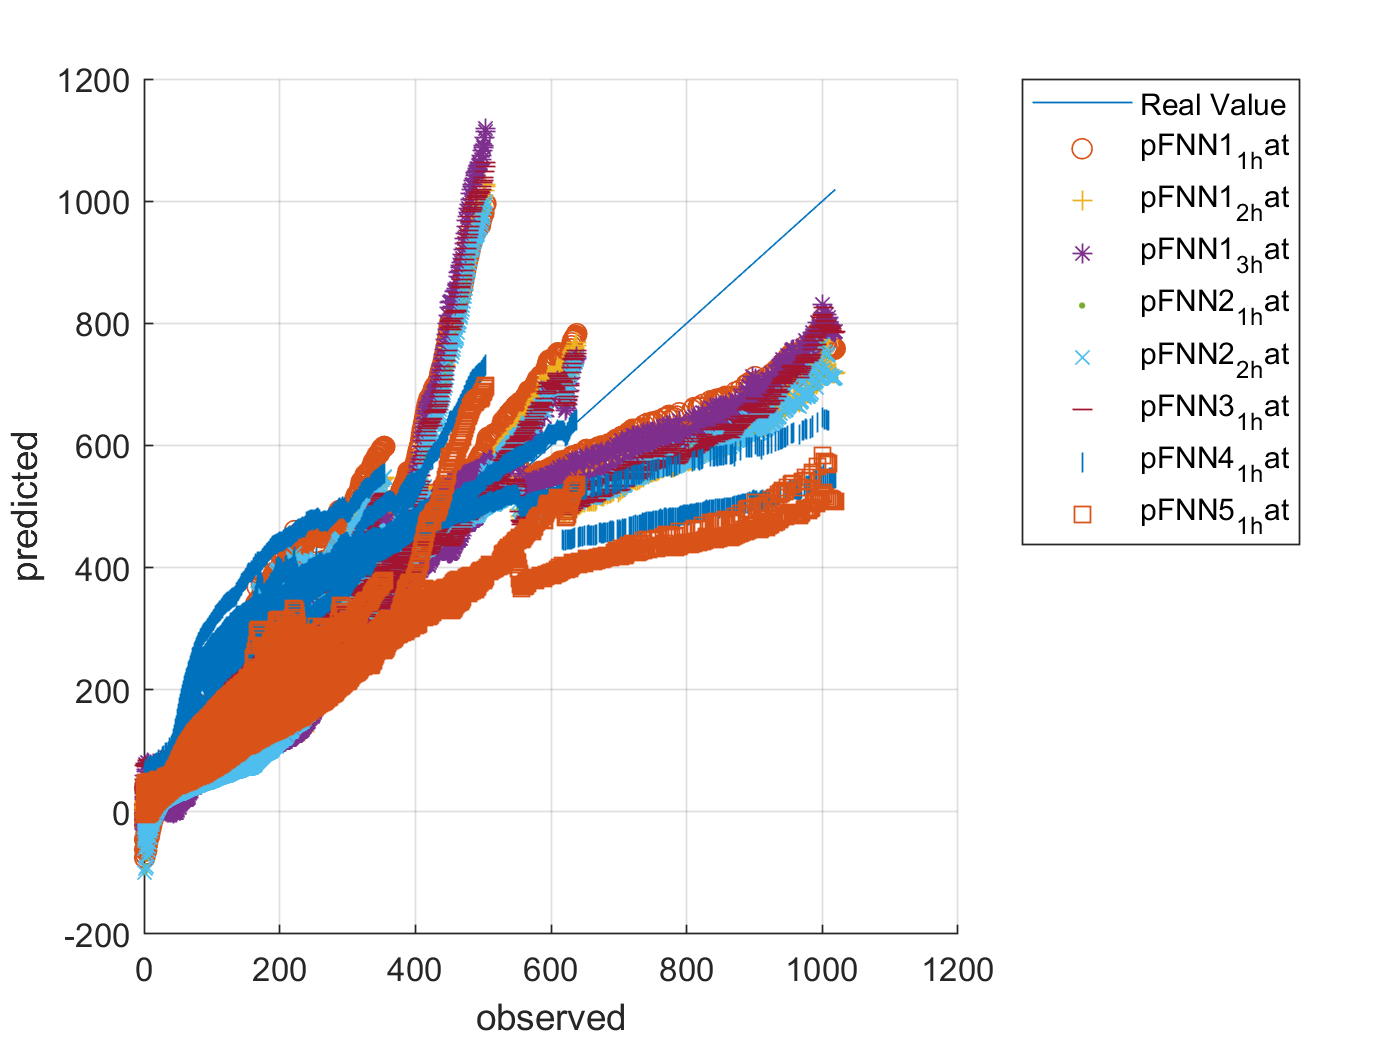



figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_1_hat,'o')
plot(ytest,pFNN1_2_hat,'+')
plot(ytest,pFNN1_3_hat,'*')
plot(ytest,pFNN2_1_hat,'.')
plot(ytest,pFNN2_2_hat,'x')
plot(ytest,pFNN3_1_hat,'_')
plot(ytest,pFNN4_1_hat,'|')
plot(ytest,pFNN5_1_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_hat', ... 
		'pFNN1_2_hat', ...
		'pFNN1_3_hat', ... 	
		'pFNN2_1_hat', ... 
		'pFNN2_2_hat', ... 
		'pFNN3_1_hat', ... 
		'pFNN4_1_hat', ... 
		'pFNN5_1_hat','Location','northeastoutside')


y_test_diff_percentage_FNN1_2_hat = abs(Y_test_Vd_RUL'-pFNN1_2_hat)./Y_test_Vd_RUL'.*100

y_test_diff_percentage_FNN1_2_hat = 	1.0e+03 *

    0.0286    0.0265    0.0263    0.0265    0.0264    0.0261    0.0263    0.0261    0.0257    0.0259    0.0261    0.0263    0.0262    0.0286    0.0297    0.0273    0.0264    0.0268    0.0271    0.0258    0.0286    0.0351    0.0400    0.0437    0.0453    0.0469    0.0473    0.0473    0.0411    0.0321    0.0228    0.0255    0.0256    0.0247    0.0243    0.0235    0.0235    0.0226    0.0221    0.0215    0.0220    0.0214    0.0232    0.0228    0.0218    0.0221    0.0231    0.0226    0.0217    0.0250


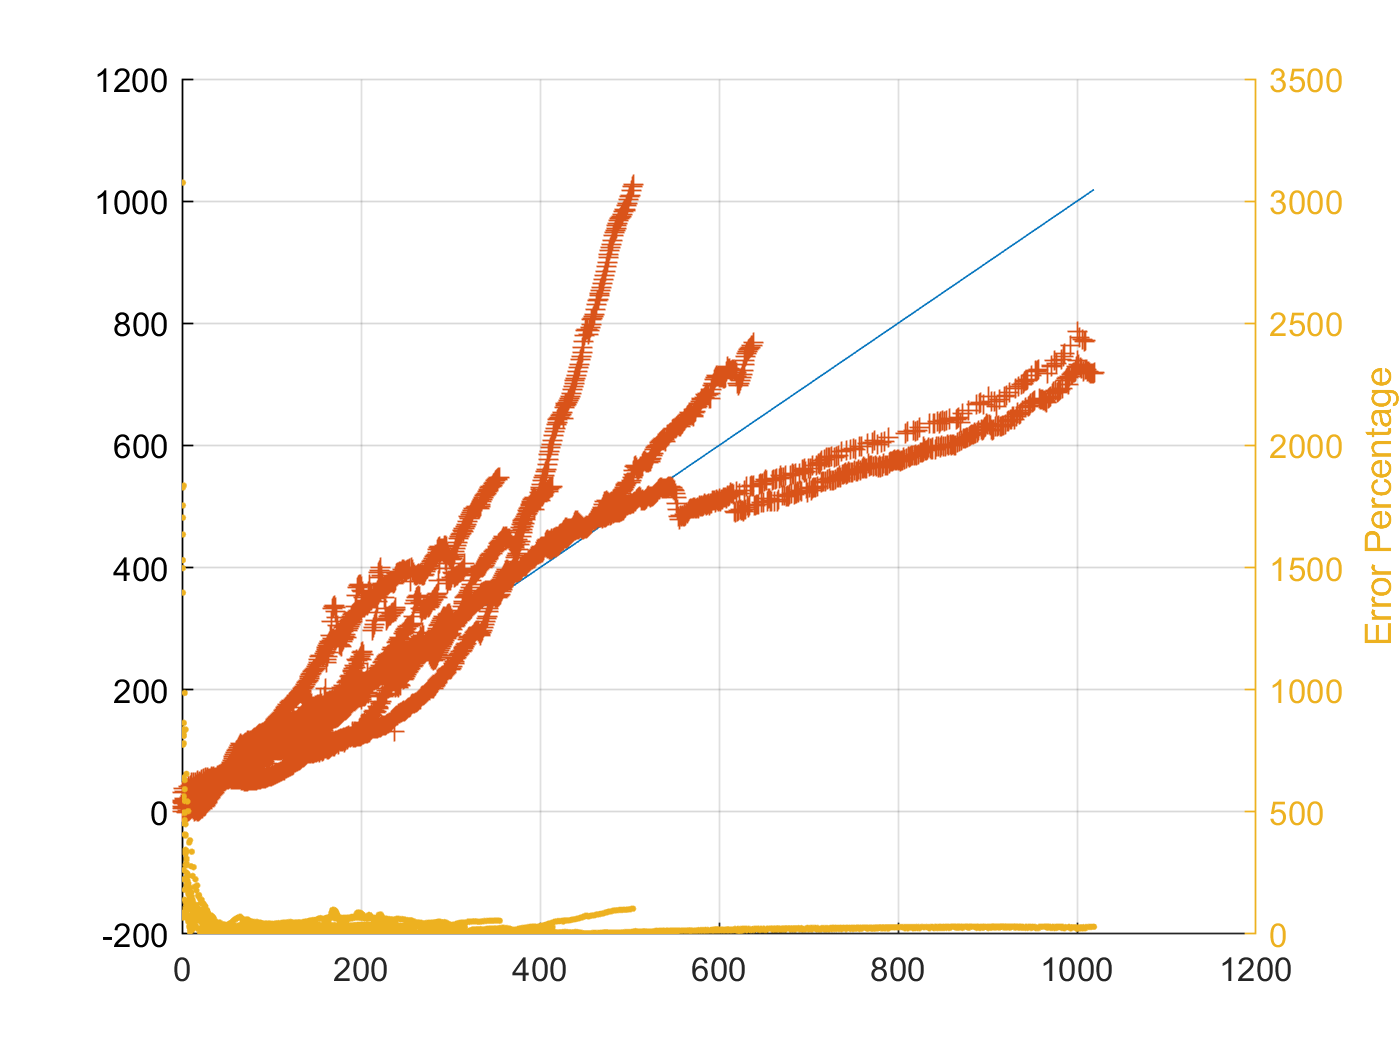

figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_2_hat,'+')

yyaxis right
ylabel('Error Percentage')
plot(ytest,y_test_diff_percentage_FNN1_2_hat,'.')

hold off

pFNN1_1_self = netFNN1_1(xnorm_Vd_RUL([idxTrainAll idxValidAll], :)');
pFNN1_2_self = netFNN1_2(xnorm_Vd_RUL([idxTrainAll idxValidAll], :)');
pFNN1_3_self = netFNN1_3(xnorm_Vd_RUL([idxTrainAll idxValidAll], :)');
pFNN2_1_self = netFNN2_1(xnorm_Vd_RUL([idxTrainAll idxValidAll], :)');
pFNN2_2_self = netFNN2_2(xnorm_Vd_RUL([idxTrainAll idxValidAll], :)');
pFNN3_1_self = netFNN3_1(xnorm_Vd_RUL([idxTrainAll idxValidAll], :)');
pFNN4_1_self = netFNN4_1(xnorm_Vd_RUL([idxTrainAll idxValidAll], :)');
pFNN5_1_self = netFNN5_1(xnorm_Vd_RUL([idxTrainAll idxValidAll], :)');

ytrain_self = ynorm_Vd_RUL([idxTrainAll idxValidAll], :)*yrate_RUL + ymin_RUL;
pFNN1_1_self_hat = pFNN1_1_self * yrate_RUL + ymin_RUL;
pFNN1_2_self_hat = pFNN1_2_self * yrate_RUL + ymin_RUL;
pFNN1_3_self_hat = pFNN1_3_self * yrate_RUL + ymin_RUL;
pFNN2_1_self_hat = pFNN2_1_self * yrate_RUL + ymin_RUL;
pFNN2_2_self_hat = pFNN2_2_self * yrate_RUL + ymin_RUL;
pFNN3_1_self_hat = pFNN3_1_self * yrate_RUL + ymin_RUL;
pFNN4_1_self_hat = pFNN4_1_self * yrate_RUL + ymin_RUL;
pFNN5_1_self_hat = pFNN5_1_self * yrate_RUL + ymin_RUL;


rmse_pFNN1_1_self_hat = sqrt(mean(( ytrain_self' - pFNN1_1_self_hat ).^2))

rmse_pFNN1_1_self_hat = 98.4440

rmse_pFNN1_2_self_hat = sqrt(mean(( ytrain_self' - pFNN1_2_self_hat ).^2))

rmse_pFNN1_2_self_hat = 84.9492

rmse_pFNN1_3_self_hat = sqrt(mean(( ytrain_self' - pFNN1_3_self_hat ).^2))

rmse_pFNN1_3_self_hat = 78.4099

rmse_pFNN2_1_self_hat = sqrt(mean(( ytrain_self' - pFNN2_1_self_hat ).^2))

rmse_pFNN2_1_self_hat = 88.4014

rmse_pFNN2_2_self_hat = sqrt(mean(( ytrain_self' - pFNN2_2_self_hat ).^2))

rmse_pFNN2_2_self_hat = 88.4014

rmse_pFNN3_1_self_hat = sqrt(mean(( ytrain_self' - pFNN3_1_self_hat ).^2))

rmse_pFNN3_1_self_hat = 83.4045

rmse_pFNN4_1_self_hat = sqrt(mean(( ytrain_self' - pFNN4_1_self_hat ).^2))

rmse_pFNN4_1_self_hat = 134.7874

rmse_pFNN5_1_self_hat = sqrt(mean(( ytrain_self' - pFNN5_1_self_hat ).^2))

rmse_pFNN5_1_self_hat = 108.2922

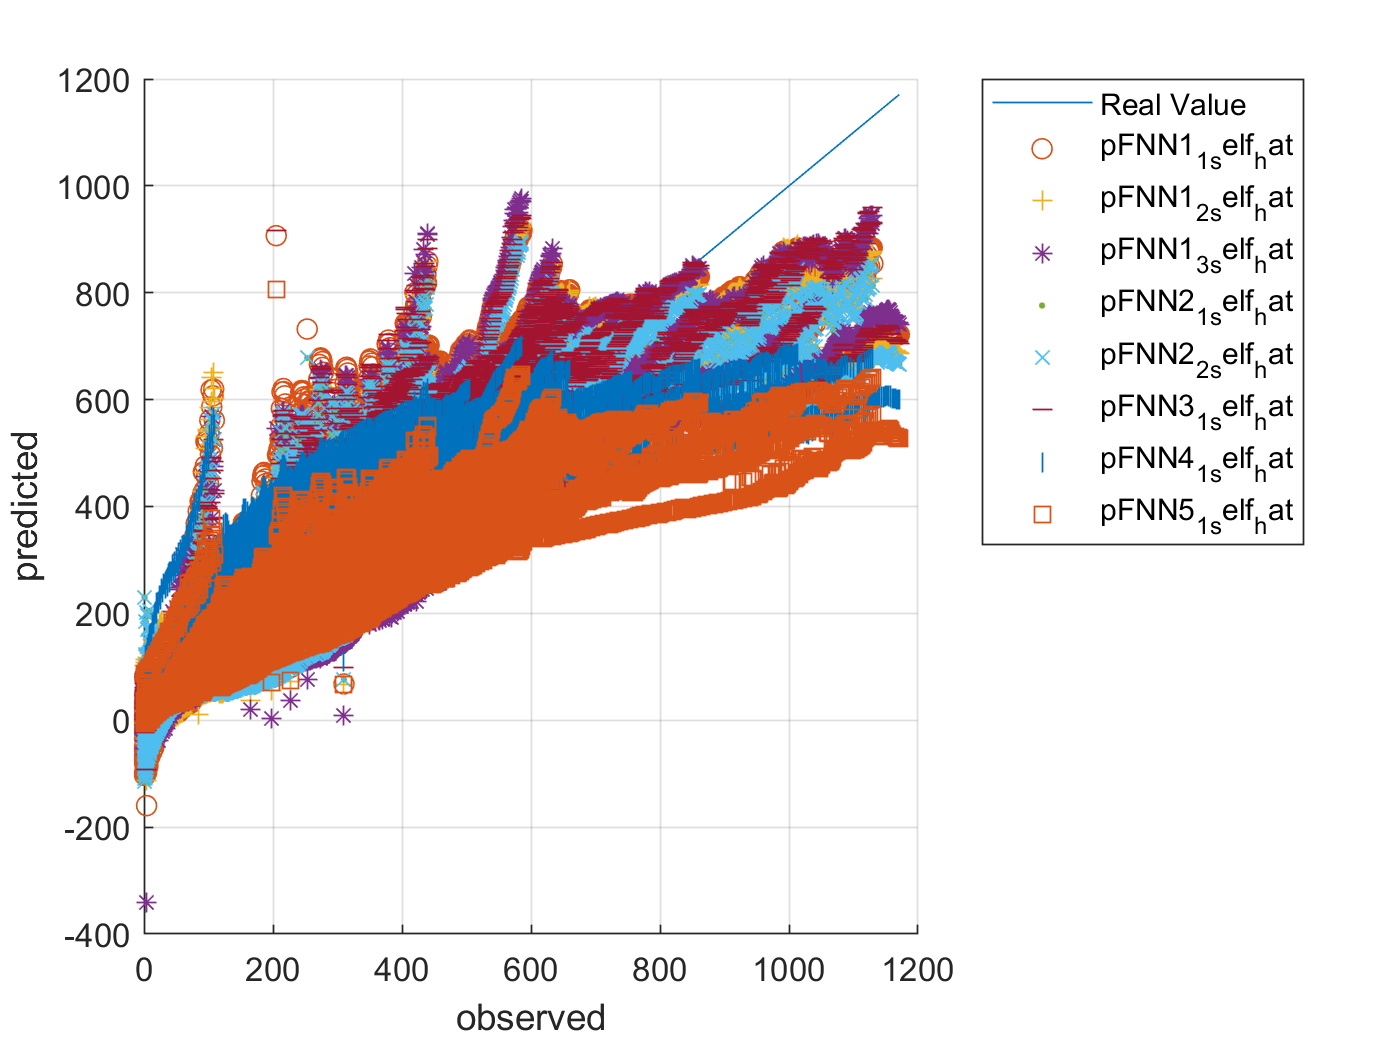



figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pFNN1_1_self_hat,'o')
plot(ytrain_self,pFNN1_2_self_hat,'+')
plot(ytrain_self,pFNN1_3_self_hat,'*')
plot(ytrain_self,pFNN2_1_self_hat,'.')
plot(ytrain_self,pFNN2_2_self_hat,'x')
plot(ytrain_self,pFNN3_1_self_hat,'_')
plot(ytrain_self,pFNN4_1_self_hat,'|')
plot(ytrain_self,pFNN5_1_self_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_self_hat', ... 
		'pFNN1_2_self_hat', ...
		'pFNN1_3_self_hat', ... 	
		'pFNN2_1_self_hat', ... 
		'pFNN2_2_self_hat', ... 
		'pFNN3_1_self_hat', ... 
		'pFNN4_1_self_hat', ... 
		'pFNN5_1_self_hat','Location','northeastoutside')

# CNN

% For CNN
filterSize = 3;
numFilters = 32;
numFCN = 1;


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.


if generate_model

layerCNN2_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
cellx = num2cell(xnorm_Vd_RUL', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(ynorm_Vd_RUL);
tbl = table(cellx);
tbl.cellyB = cellyB;


Traintbl = tbl(idxTrainAll, :);
valtbl = tbl(idxValidAll, :);
testtbl = tbl(idxTestAll, :);

options = trainingOptions('adam', ...
 'InitialLearnRate', 0.001, ...
 'MaxEpochs',epoc_count, ...
 'MiniBatchSize',50, ...
 'Plots','training-progress', 'ValidationData', valtbl);

tic
netCNN2_1 = trainNetwork(Traintbl, layerCNN2_1, options);
toc




- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:15 |         0.26 |         0.26 |       0.0326 |       0.0339 |          0.0010 |
|       1 |          50 |       00:00:22 |         0.14 |         0.10 |       0.0097 |       0.0053 |          0.0010 |
|       1 |         100 |       00:00:25 |         0.05 |         0.08 |       0.0014 |       0.0030 |          0.0010 |
|       1 |         150 |       00:00:31 |         0.05 |         0.07 |       0.0015 |   

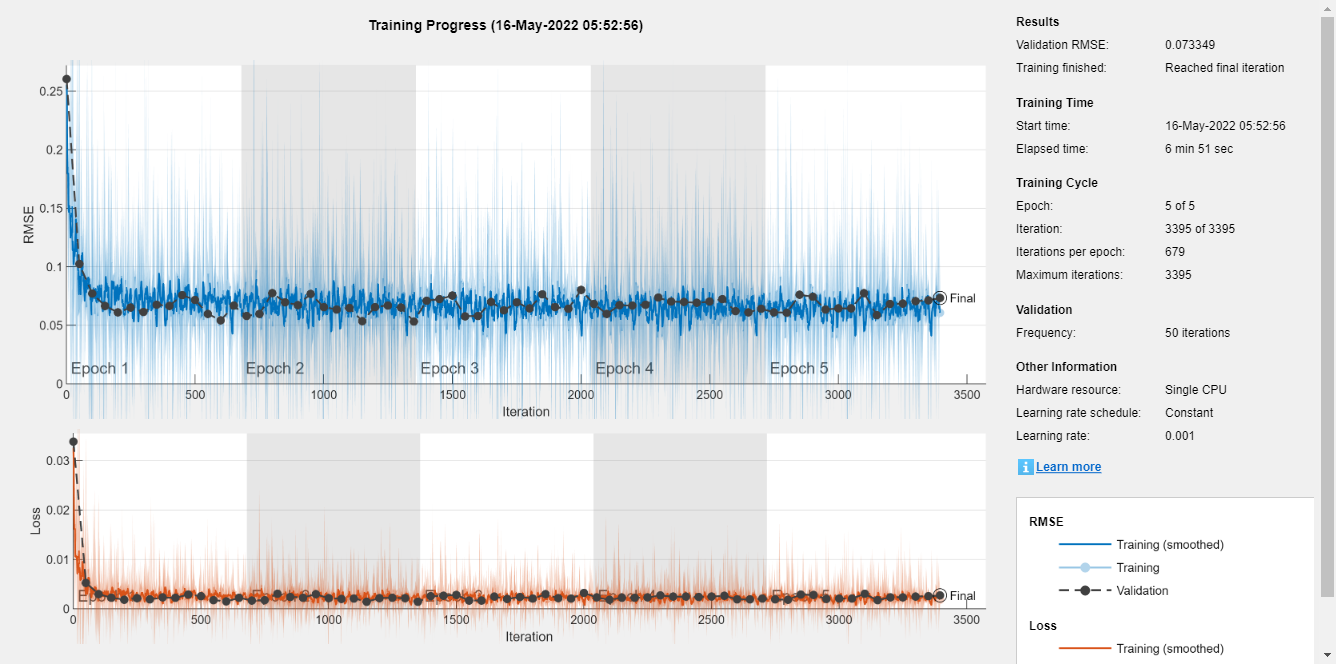

Elapsed time is 429.280178 seconds.


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |         0.28 |         0.25 |       0.0386 |       0.0324 |          0.0010 |
|       1 |          50 |       00:00:20 |         0.11 |         0.09 |       0.0058 |       0.0044 |          0.0010 |
|       1 |         100 |       00:00:31 |         0.10 |         0.07 |       0.0052 |       0.0024 |          0.0010 |
|       1 |         150 |       00:00:36 |         0.10 |         0.07 |       0.0050 |   

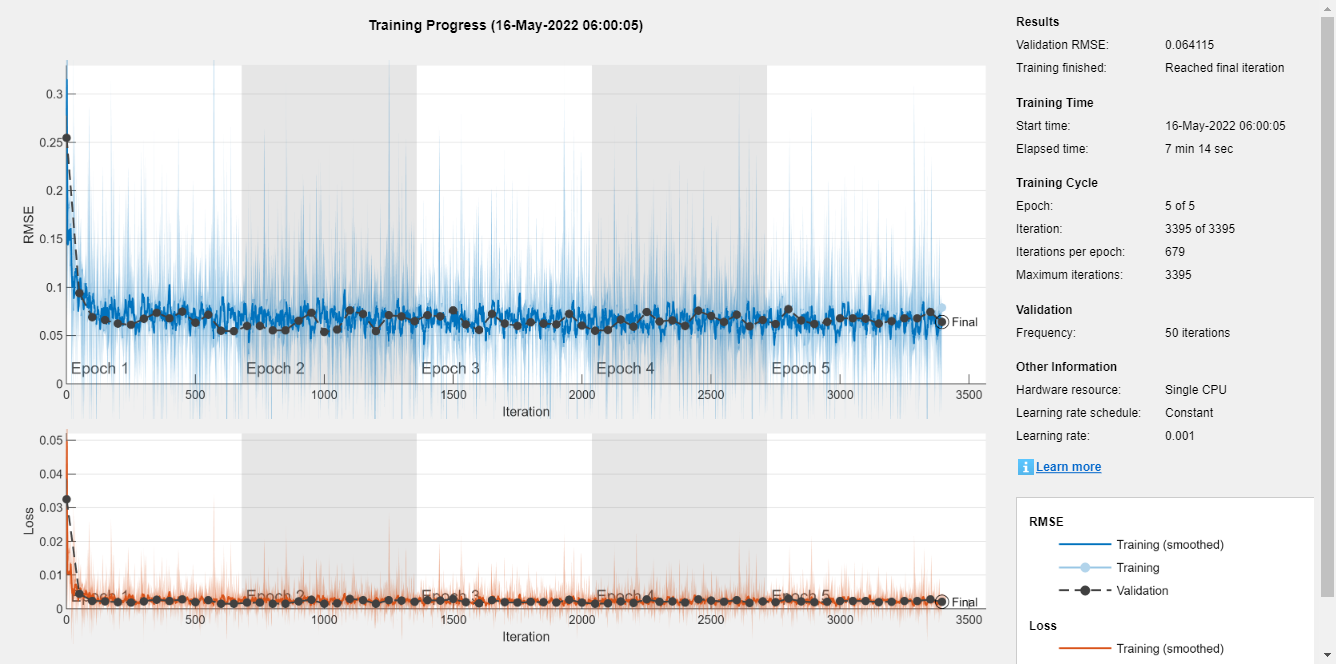

Elapsed time is 452.947244 seconds.


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:23 |         0.33 |         0.29 |       0.0545 |       0.0434 |          0.0010 |
|       1 |          50 |       00:00:30 |         0.12 |         0.12 |       0.0077 |       0.0069 |          0.0010 |
|       1 |         100 |       00:00:35 |         0.11 |         0.09 |       0.0056 |       0.0042 |          0.0010 |
|       1 |         150 |       00:00:42 |         0.13 |         0.08 |       0.0079 |   

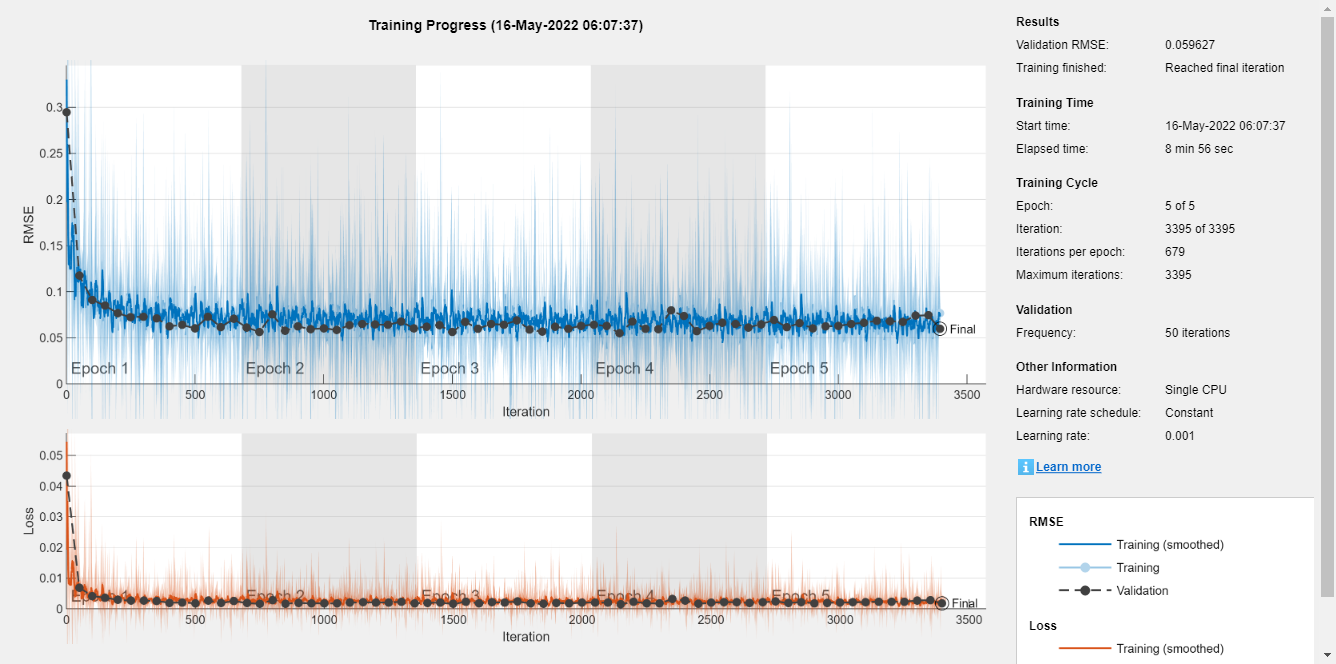

Elapsed time is 552.817731 seconds.


layerCNN2_2 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];

tic
netCNN2_2 = trainNetwork(Traintbl, layerCNN2_1, options);
toc

layerCNN1_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
%     sequenceInputLayer(input_size)
%     convolution1dLayer(filterSize,numFilters)
%     reluLayer
%     globalMaxPooling1dLayer
%     fullyConnectedLayer(numFCN)
%     %softmaxLayer
%     regressionLayer();]
tic
netCNN1_1 = trainNetwork(Traintbl, layerCNN1_1, options);
toc

%%%% 시간이 오래 걸린다. 
%{
layerCNN2_3 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
tic
netCNN2_3 = trainNetwork(Traintbl, layerCNN2_3, options);
toc

layerCNN2_4 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
     reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
tic
netCNN2_4 = trainNetwork(Traintbl, layerCNN2_4, options);
toc


figure
plot(xnorm_Vd_RUL')
xlabel("Qc")
title("Training Observation 1")
numFeatures = size(xnorm_Vd_RUL,1);
legend("Feature " + string(1:numFeatures),Location="northeastoutside")
%}
%%%%%%%%%%%%%%

save('ryan3_model_Vd_RUL.mat','netCNN2_1' ,'-append')
save('ryan3_model_Vd_RUL.mat','netCNN2_2' ,'-append')
%save('ryan3_model_Vd_RUL.mat','netCNN2_3' ,'-append')
%save('ryan3_model_Vd_RUL.mat','netCNN2_4' ,'-append')
save('ryan3_model_Vd_RUL.mat','netCNN1_1' ,'-append')

end


cellx = num2cell(xnorm_Vd_RUL(idxTestAll, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, cc_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN2_1 = predict(netCNN2_1, x_4d);
pCNN2_2 = predict(netCNN2_2, x_4d);
%pCNN2_3 = predict(netCNN2_3, x_4d);
%pCNN2_4 = predict(netCNN2_4, x_4d);
pCNN1_1 = predict(netCNN1_1, x_4d);



ytest = ynorm_Vd_RUL(idxTestAll, :)*yrate_RUL + ymin_RUL;
pCNN2_1_hat = pCNN2_1 * yrate_RUL + ymin_RUL;
pCNN2_2_hat = pCNN2_2 * yrate_RUL + ymin_RUL;
%pCNN2_3_hat = pCNN2_3 * yrate_RUL + ymin_RUL;
%pCNN2_4_hat = pCNN2_4 * yrate_RUL + ymin_RUL;
pCNN1_1_hat = pCNN1_1 * yrate_RUL + ymin_RUL;


rmse_pCNN2_1_hat = sqrt(mean(( ytest' - pCNN2_1_hat' ).^2))

rmse_pCNN2_1_hat = single
85.9908

rmse_pCNN2_2_hat = sqrt(mean(( ytest' - pCNN2_2_hat' ).^2))

rmse_pCNN2_2_hat = single
83.0240

%rmse_pCNN2_3_hat = sqrt(mean(( ytest' - pCNN2_3_hat' ).^2))
%rmse_pCNN2_4_hat = sqrt(mean(( ytest' - pCNN2_4_hat' ).^2))
rmse_pCNN1_1_hat = sqrt(mean(( ytest' - pCNN1_1_hat' ).^2))

rmse_pCNN1_1_hat = single
85.3925

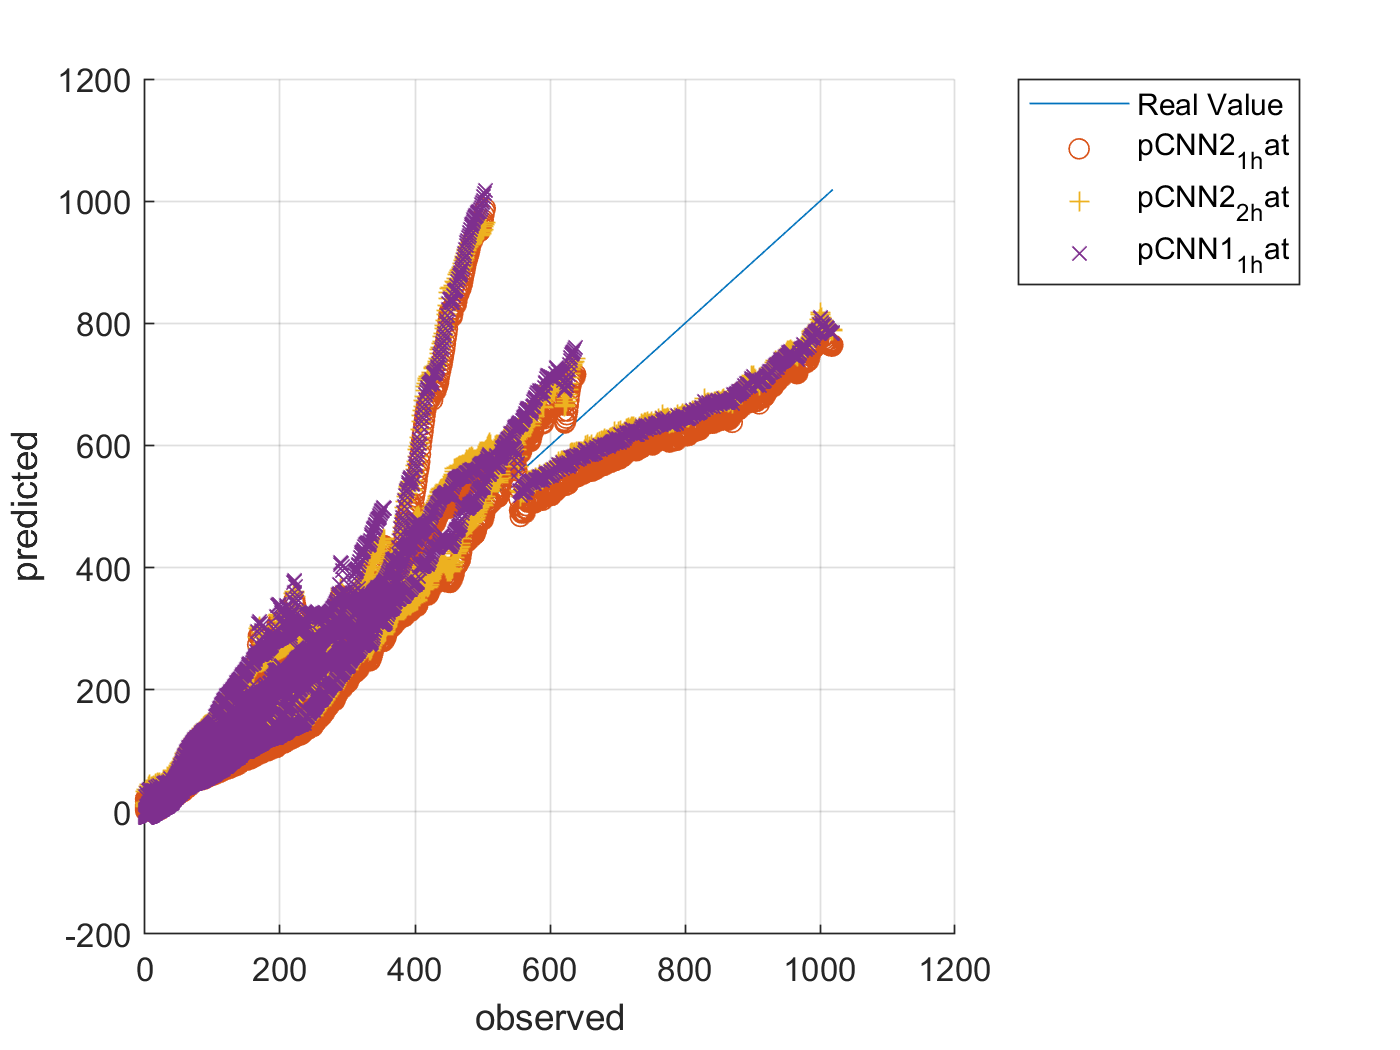




figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pCNN2_1_hat,'o')
plot(ytest,pCNN2_2_hat,'+')
%plot(ytest,pCNN2_3_hat,'*')
%plot(ytest,pCNN2_4_hat,'.')
plot(ytest,pCNN1_1_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_hat', ... 
		'pCNN2_2_hat', ...
		'pCNN1_1_hat','Location','northeastoutside')






cellx_self = num2cell(xnorm_Vd_RUL([idxTrainAll idxValidAll], :)', 1)';
cellx_self = cellfun(@transpose, cellx_self, 'UniformOutput', false);
tbl_self = table(cellx_self);

x_4d_self = zeros(1, cc_input_size, 1, height(tbl_self));
for i = 1:height(tbl_self)
    x_4d_self(:,:,:,i) = tbl_self.cellx_self{i};
end

pCNN2_1_self = predict(netCNN2_1, x_4d_self);
pCNN2_2_self = predict(netCNN2_2, x_4d_self);
%pCNN2_3_self = predict(netCNN2_3, x_4d_self);
%pCNN2_4_self = predict(netCNN2_4, x_4d_self);
pCNN1_1_self = predict(netCNN1_1, x_4d_self);

ytrain_self = ynorm_Vd_RUL([idxTrainAll idxValidAll], :)*yrate_RUL + ymin_RUL;
pCNN2_1_self_hat = pCNN2_1_self * yrate_RUL + ymin_RUL;
pCNN2_2_self_hat = pCNN2_2_self * yrate_RUL + ymin_RUL;
%pCNN2_3_self_hat = pCNN2_3_self * yrate_RUL + ymin_RUL;
%pCNN2_4_self_hat = pCNN2_4_self * yrate_RUL + ymin_RUL;
pCNN1_1_self_hat = pCNN1_1_self * yrate_RUL + ymin_RUL;


rmse_pCNN2_1_self_hat = sqrt(mean(( ytrain_self' - pCNN2_1_self_hat' ).^2))

rmse_pCNN2_1_self_hat = single
77.9416

rmse_pCNN2_2_self_hat = sqrt(mean(( ytrain_self' - pCNN2_2_self_hat' ).^2))

rmse_pCNN2_2_self_hat = single
75.2542

%rmse_pCNN2_3_self_hat = sqrt(mean(( ytrain_self' - pCNN2_3_self_hat' ).^2))
%rmse_pCNN2_4_self_hat = sqrt(mean(( ytrain_self' - pCNN2_4_self_hat' ).^2))
rmse_pCNN1_1_self_hat = sqrt(mean(( ytrain_self' - pCNN1_1_self_hat' ).^2))

rmse_pCNN1_1_self_hat = single
78.6067

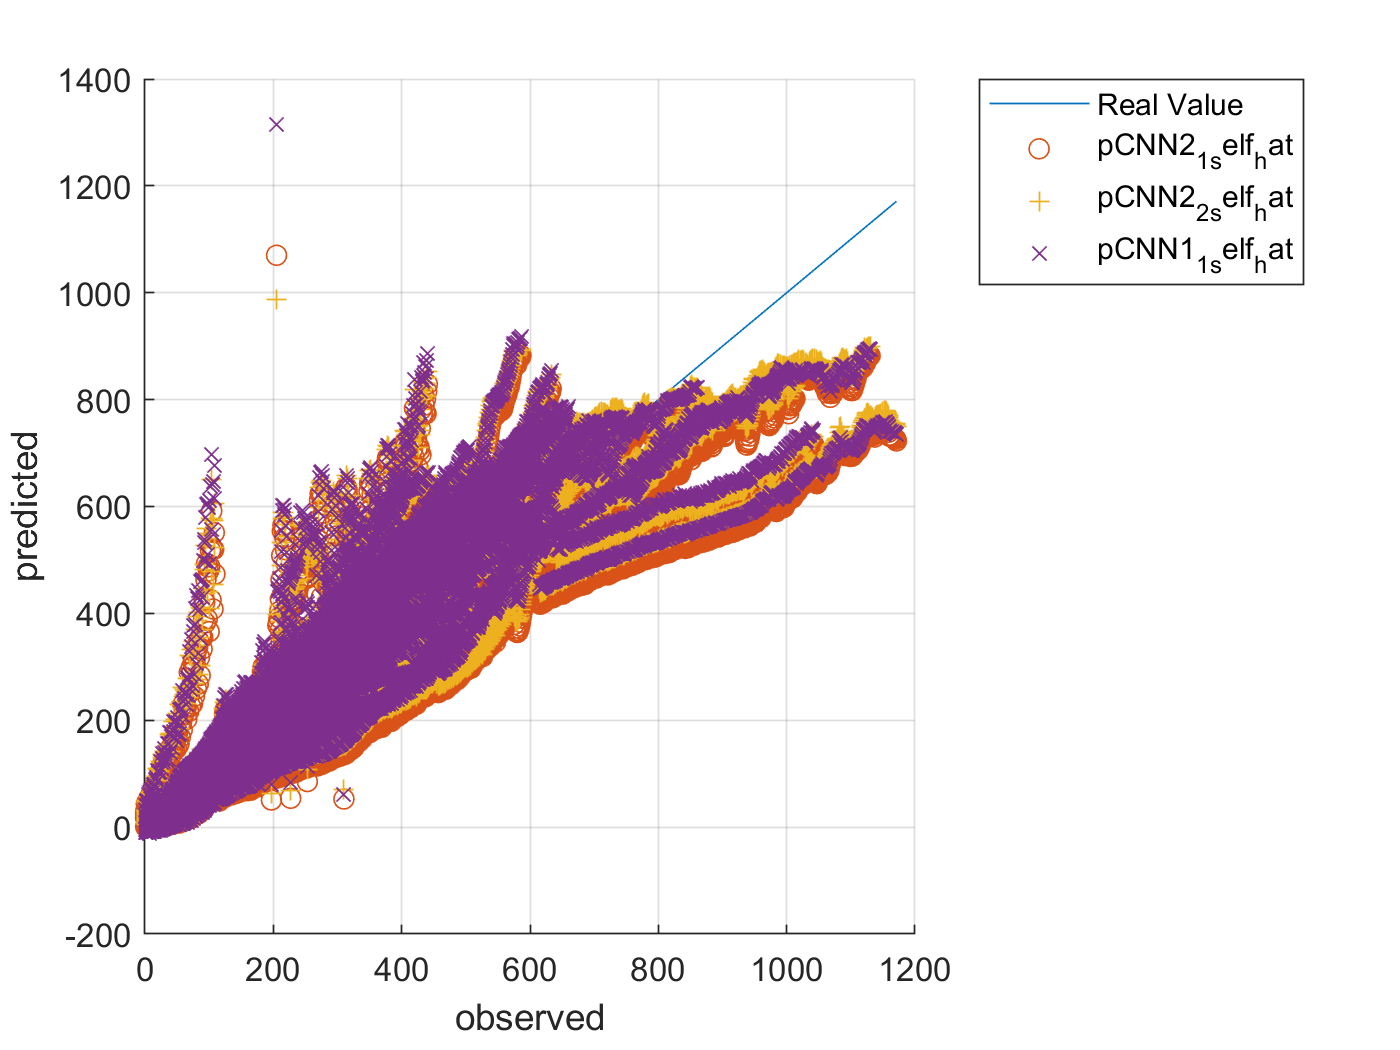




figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pCNN2_1_self_hat,'o')
plot(ytrain_self,pCNN2_2_self_hat,'+')
%plot(ytrain_self,pCNN2_3_self_hat,'*')
%plot(ytrain_self,pCNN2_4_self_hat,'.')
plot(ytrain_self,pCNN1_1_self_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_self_hat', ... 
		'pCNN2_2_self_hat', ...
		'pCNN1_1_self_hat','Location','northeastoutside')

# LSTM

- LSTM : 1 lstm layer with 5 hidden units

cc_input_size = 20;
numHiddenUnits = 50;

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:15 |         0.30 |         0.30 |       0.0455 |       0.0463 |          0.0010 |
|       1 |          50 |       00:00:21 |         0.13 |         0.13 |       0.0082 |       0.0090 |          0.0010 |
|       1 |         100 |       00:00:36 |         0.11 |         0.10 |       0.0060 |       0.0053 |          0.0010 |
|       1 |         150 |       00:00:53 |         0.10 |         0.09 |       0.0051 |       0.0044 |          0.0010 |
|       

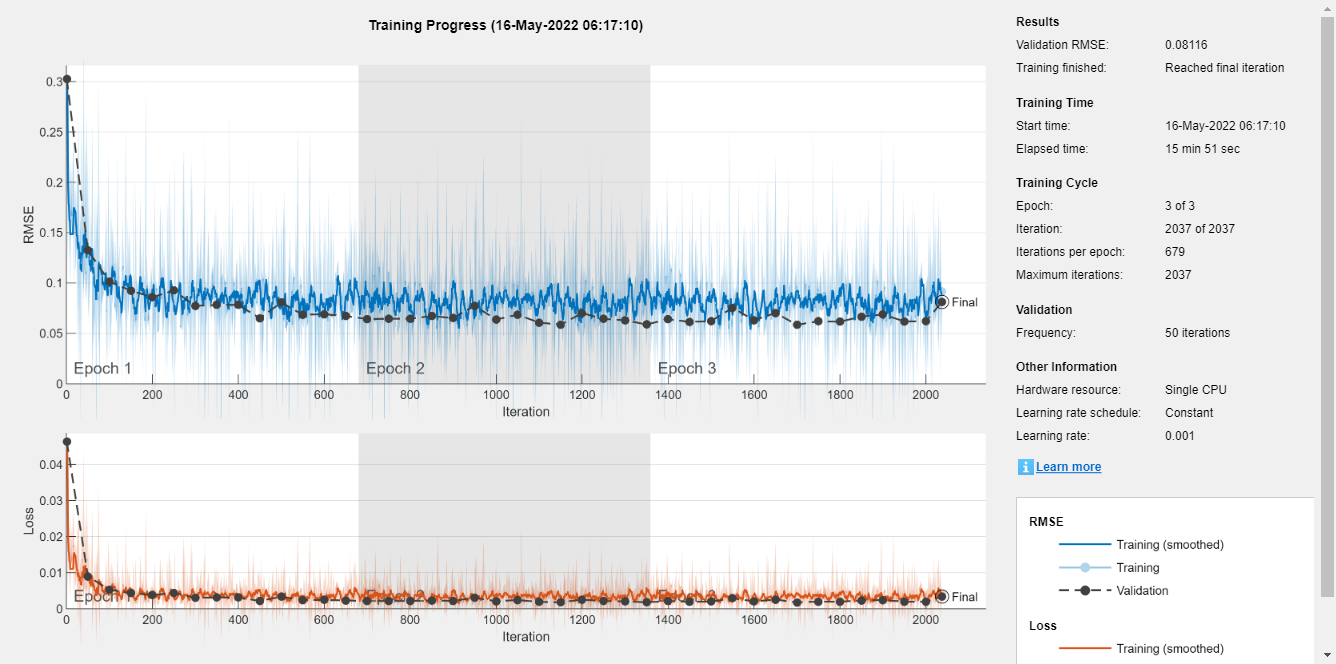

Elapsed time is 989.004873 seconds.


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:17 |         0.28 |         0.30 |       0.0390 |       0.0443 |          0.0010 |
|       1 |          50 |       00:00:30 |         0.17 |         0.17 |       0.0140 |       0.0141 |          0.0010 |
|       1 |         100 |       00:00:38 |         0.08 |         0.11 |       0.0035 |       0.0066 |          0.0010 |
|       1 |         150 |       00:00:49 |         0.10 |         0.09 |       0.0051 |       0.0044 |          0.0010 |
|       

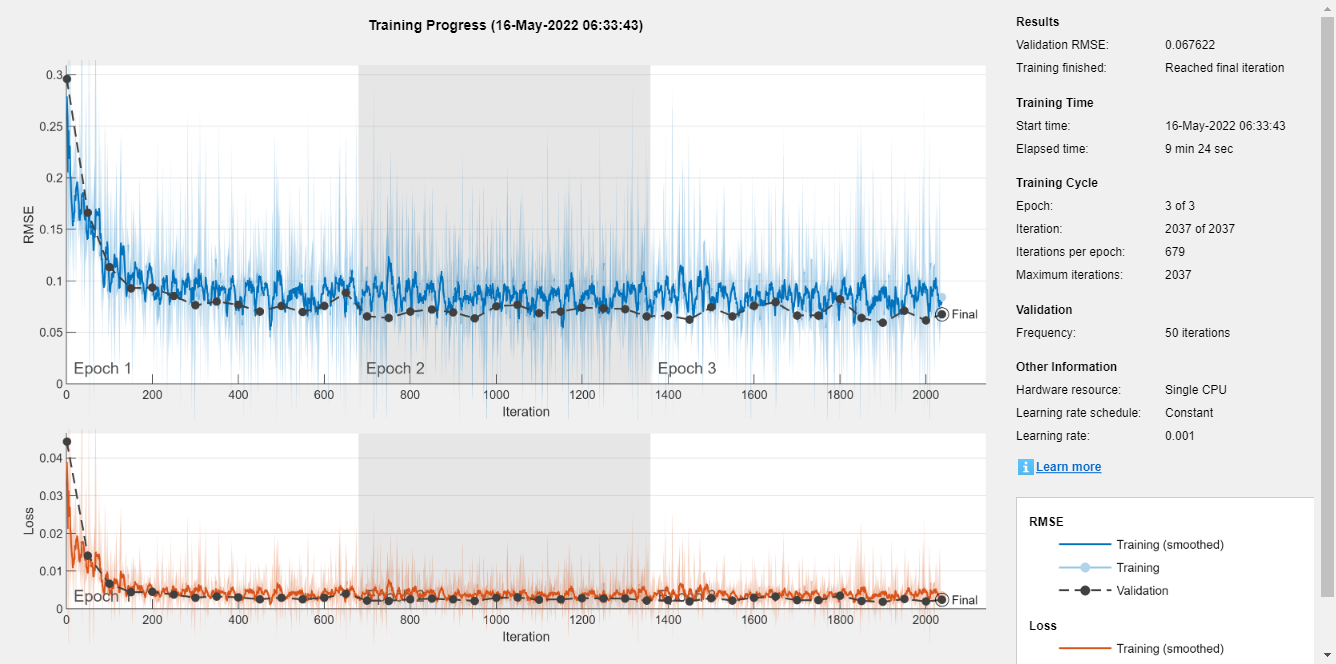

Elapsed time is 600.352174 seconds.



if generate_model
layersLSTM = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

layersLSTM2 = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(xnorm_Vd_RUL', 1)';
cellyB = num2cell(ynorm_Vd_RUL);

traincellx = cellx(idxTrainAll, :);
valcellx = cellx(idxValidAll, :);
testcellx = cellx(idxTestAll, :);

traincellyB = cellyB(idxTrainAll, :);
valcellyB = cellyB(idxValidAll, :);
testcellyB = cellyB(idxTestAll, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',epoc_count_lstm, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

tic
netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);
toc 

tic
netLSTM2 = trainNetwork(traincellx, traincellyB, layersLSTM2, options);
toc

save('ryan3_model_Vd_RUL.mat','netLSTM' ,'-append')
save('ryan3_model_Vd_RUL.mat','netLSTM2' ,'-append')

end


pLSTM = cell2mat(predict(netLSTM, num2cell(xnorm_Vd_RUL(idxTestAll, :)', 1)));
pLSTM2 = cell2mat(predict(netLSTM2, num2cell(xnorm_Vd_RUL(idxTestAll, :)', 1)));
ytest = ynorm_Vd_RUL(idxTestAll, :)*yrate_RUL + ymin_RUL;
pLSTM_hat = pLSTM * yrate_RUL + ymin_RUL;
pLSTM2_hat = pLSTM2 * yrate_RUL + ymin_RUL;
rmse_pLSTM_hat = sqrt(mean(( ytest' - pLSTM_hat' ).^2))

rmse_pLSTM_hat = single
117.1446

rmse_pLSTM2_hat = sqrt(mean(( ytest' - pLSTM_hat' ).^2))

rmse_pLSTM2_hat = single
117.1446

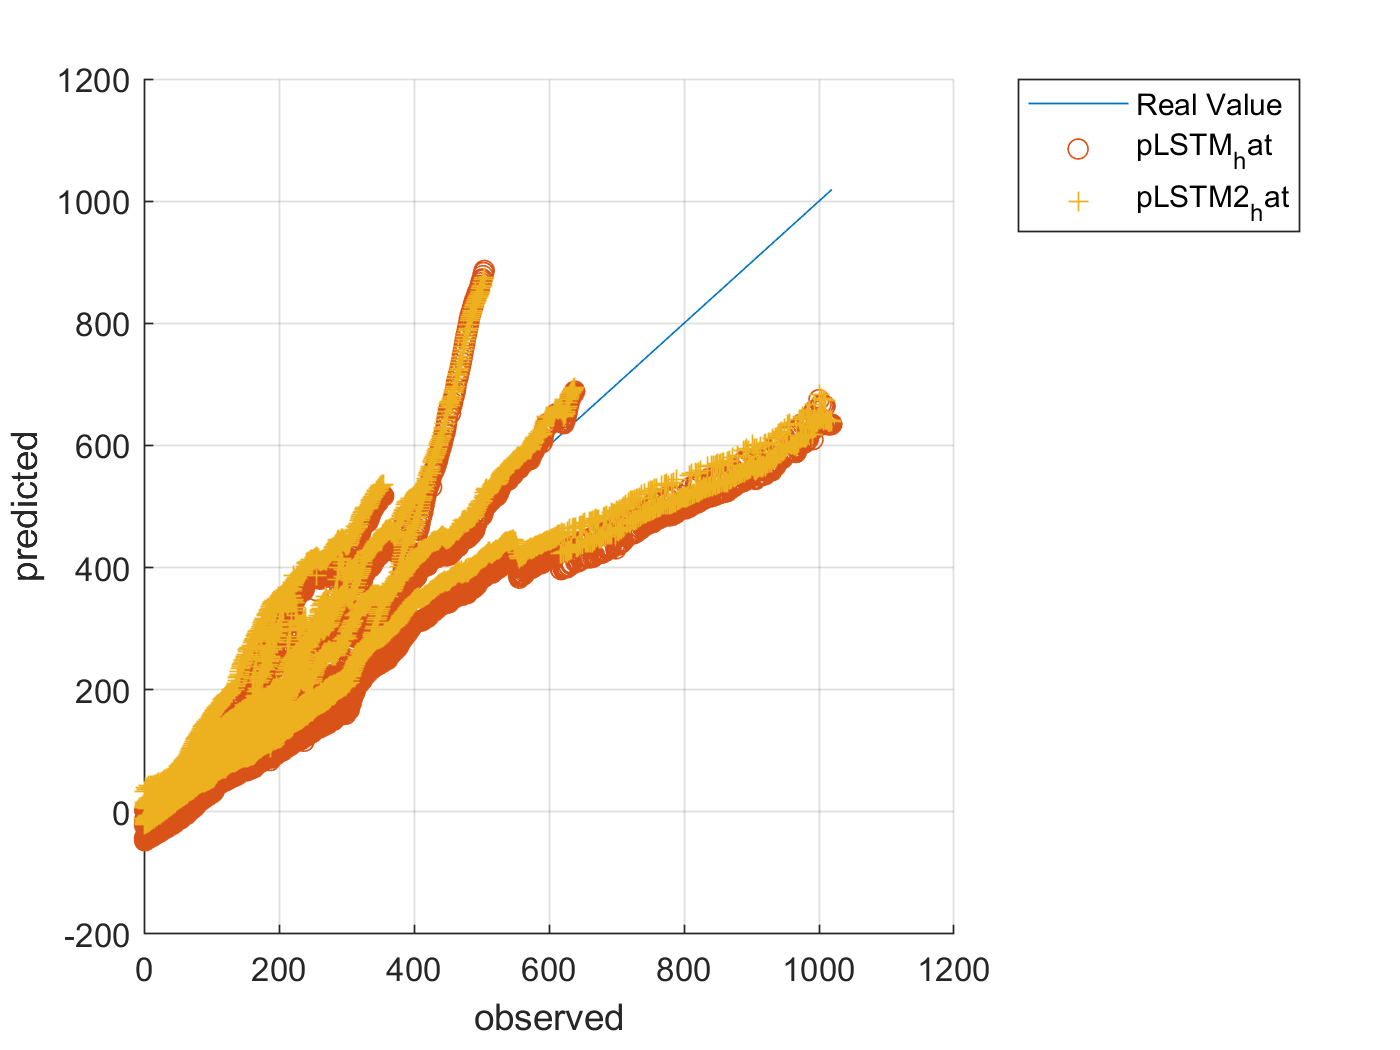



figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pLSTM_hat,'o')
plot(ytest,pLSTM2_hat,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM_hat', ...
        'pLSTM2_hat','Location','northeastoutside')



pLSTM_self = cell2mat(predict(netLSTM, num2cell(xnorm_Vd_RUL([idxTrainAll idxValidAll], :)', 1)));
pLSTM2_self = cell2mat(predict(netLSTM2, num2cell(xnorm_Vd_RUL([idxTrainAll idxValidAll], :)', 1)));
ytrain_self = ynorm_Vd_RUL([idxTrainAll idxValidAll], :)*yrate_RUL + ymin_RUL;
pLSTM_self = pLSTM_self * yrate_RUL + ymin_RUL;
pLSTM2_self = pLSTM2_self * yrate_RUL + ymin_RUL;
rmse_pLSTM_self_hat = sqrt(mean(( ytrain_self' - pLSTM_self' ).^2))

rmse_pLSTM_self_hat = single
102.2836

rmse_pLSTM2_self_hat = sqrt(mean(( ytrain_self' - pLSTM2_self' ).^2))

rmse_pLSTM2_self_hat = single
94.7866

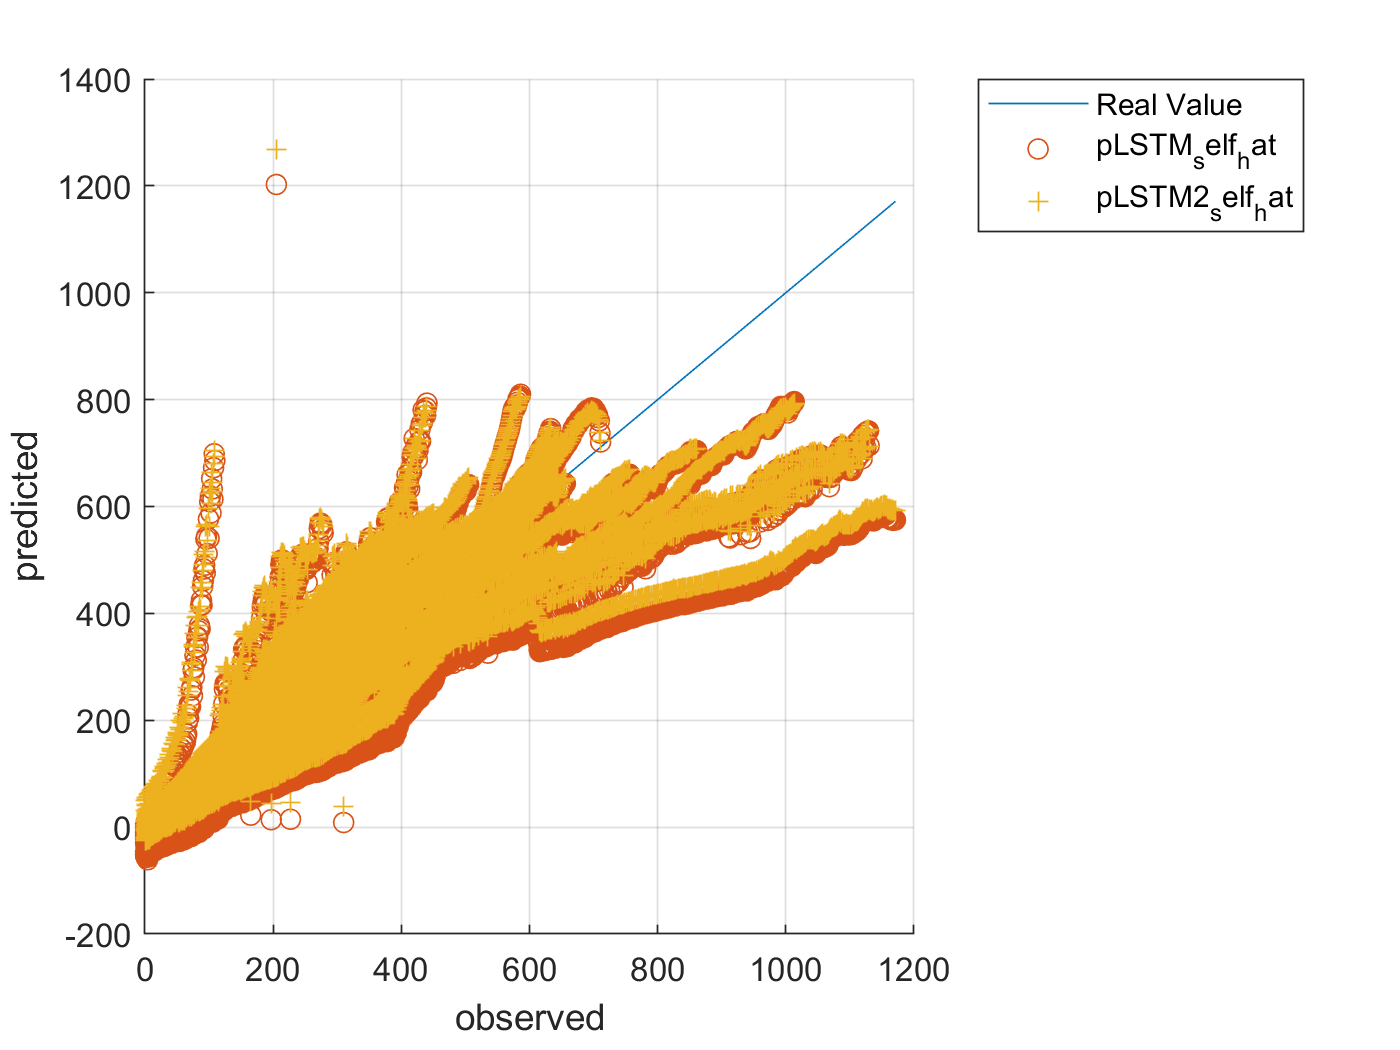


figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pLSTM_self,'o')
plot(ytrain_self,pLSTM2_self,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM_self_hat', ...
        'pLSTM2_self_hat','Location','northeastoutside')